clear all
addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

species='Humans'; 

plot_indiv_subj=0; % turn on/off single subject graphs

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

% Labels for allvisual-
% IMPORTANT: some subjects might not have all ROIs
if strcmp(species,'Humans')
    allvisual_numbers=[1,2,3,4,5,6,150,151,152,153,154,50,51,52,100,101,102,103];
    allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','V7','LO1','LO2','TO1','TO2'};
    EVCrois=[1,2,3,4,5,6];
    V4rois=[7];
    dorsalrois=[12,13,14];
    lateralrois=[15,16,17,18];
    ventralrois=[8,9,10,11];
    use_colorscale=[0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
elseif strcmp(species,'Monks')
     allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,52,53,54,55,56,100,101,102,103];
     allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','V4v','V4d','V4Av','V4Ad','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};       
     EVCrois=[1,2,3,4,5,6];
     V4rois=[7,8,9,10];
     dorsalrois=[16,17,18,19,20,21,22];
     lateralrois=[23,24,25,26];
     ventralrois=[11,12,13,14,15];
     use_colorscale=[0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 1; 1 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
else
   fprintf('Error. Unknown species.\n')
end

nodearea_smoothwm_col=2;
nodearea_pial_col=3;
triarea_smoothwm_col=4;
triarea_pial_col=5;
nodevol_col=6;
nodethickness_col=7;

% This should be a more efficient way of filtering the directories:
files = dir(data_dir);
names = {files.name}; 
dirFlags = [files.isdir] & ~strcmp(names, '.') & ~strcmp(names, '..') & ~strcmp(names, 'phasemaps') & ~strcmp(names, 'VTPM') & ~strcmp(names, 'VTPM_delayedsaccade') & ~strcmp(names, 'MNI') & ~strcmp(names, 'ignore');
subjs=names(dirFlags);
norois=[];

% cd(data_dir)

% Make LGN files
%  for curr_subj = 1:size(subjs,2)
%      cd(num2str(subjs{curr_subj}))
%      cd rois
%      unix(['/Users/marcaro/abin/3dROIstats -nzvolume -mask ' num2str(subjs{curr_subj}) '_LGN+orig ' num2str(subjs{curr_subj}) '_LGN+orig > ' num2str(subjs{curr_subj}) '_LGN.1D'])
%      cd ../../
%  end


for curr_subj = 1:size(subjs,2)
%     cd(num2str(subjs{curr_subj}))
    subj_dir = ['./',species,'/',num2str(subjs{curr_subj}),'/'];

    % File w/ various measures of cortical surface contains 7 columns (use 2 & 3 for area): 
    % 1) node index
    % 2) node area along smoothwm surface
    % 3) node area along pial surface
    % 4) avg triangle area of associated node along smoothwm surface
    % 5) avg triangle area of associated node along pial surface
    % 6) node volume between smoothwm and pial
    % 7) node thickness (Euclidean distance between smoothwm and pial)
    % To calculate total surface area, sum across all nodes
    surfmeasures_rh=Read_1D([subj_dir,num2str(subjs{curr_subj}) '_surfmeasures_rh.1D.dset']);
    surfmeasures_lh=Read_1D([subj_dir,num2str(subjs{curr_subj}) '_surfmeasures_lh.1D.dset']);
    
    % ROI files for retinotopic maps w/ 2 columns:
    % 1) node index
    % 2) binary value identifying area assigned to each node (0 = no vis area)
    % see allvisual_numbers and allvisual_labels for identification of each area
    % this is also listed in the areal_labels file
    % IMPORTANT: file has incomplete note list. only has data for nodes in
    % visual areas
    if exist([subj_dir,'rois/allvisual-rh.1D.dset'])
        if strcmp(num2str(species),'Humans')
            allvisual_rh=Read_1D([subj_dir,'rois/allvisual-rh_fovfill.1D.dset']);
            allvisual_lh=Read_1D([subj_dir,'rois/allvisual-lh_fovfill.1D.dset']);
        else
            allvisual_rh=Read_1D([subj_dir,'rois/allvisual-rh.1D.dset']);
            allvisual_lh=Read_1D([subj_dir,'rois/allvisual-lh.1D.dset']);
        end
    else
        fprintf(['No allvisual in ' num2str(subjs{curr_subj}) '\n']);
        norois=[norois,curr_subj];
    end
    if exist([subj_dir,'rois/' num2str(subjs{curr_subj}) '_LGN.1D'])
        temp=load([subj_dir,'rois/' num2str(subjs{curr_subj}) '_LGN.1D']);
        if ~isempty(temp)
            all_LGN_rh(curr_subj)=temp(2);
            all_LGN_lh(curr_subj)=temp(4);
        else
            all_LGN_rh(curr_subj)=nan;
            all_LGN_lh(curr_subj)=nan;
        end
    end
    
    % Surface curvature files w/ 1 columns:
    % 1) surface curvature value 
    % node index = [0:length(curv_rh)-1]
    curv_rh=Read_1D([subj_dir,'rh.curv.1D.dset']);
    curv_lh=Read_1D([subj_dir,'lh.curv.1D.dset']);
    
    % Surface sulcal depth files w/ 1 columns:
    % 1) surface sulcal depth value     
    % node index = [0:length(sulc_rh)-1]
    sulc_rh=Read_1D([subj_dir,'rh.sulc.1D.dset']);
    sulc_lh=Read_1D([subj_dir,'lh.sulc.1D.dset']);

    % Surface thickness files w/ 1 columns:
    % 1) surface thickness value  
    % node index = [0:length(thickness_rh)-1]
    thickness_rh=Read_1D([subj_dir,'rh.thickness.1D.dset']);
    thickness_lh=Read_1D([subj_dir,'lh.thickness.1D.dset']);
    
    %neccessary to create graphs 
    clear h_combined_per_subject;
    clear subject_wm_rh;
    clear subject_wm_lh;
    clear figure
    
    V1nodes_rh=allvisual_rh(allvisual_rh(:,2)==1 | allvisual_rh(:,2)==2);
    V1nodes_lh=allvisual_lh(allvisual_lh(:,2)==1 | allvisual_lh(:,2)==2);
    allothernodes_rh=allvisual_rh(allvisual_rh(:,2)>2);
    allothernodes_lh=allvisual_lh(allvisual_lh(:,2)>2);   
    %MTnodes_rh=allvisual_rh(allvisual_rh(:,2)==100);
    %MTnodes_lh=allvisual_lh(allvisual_lh(:,2)==100);
    %MTallothernodes_rh=allvisual_rh(allvisual_rh(:,2)~=100);
    %MTallothernodes_lh=allvisual_lh(allvisual_lh(:,2)~=100);  
    V1allnodepairs_rh=[];
    for x = 1:ceil(length(V1nodes_rh)/10):length(V1nodes_rh)
        V1allnodepairs_rh=[V1allnodepairs_rh;[repmat(V1nodes_rh(x),[length(allothernodes_rh) 1]),allothernodes_rh]];
    end
    save([subj_dir,'V1nodepairs_rh.1D.dset'],'V1allnodepairs_rh','-ascii')
    
    V1allnodepairs_lh=[];
    for x = 1:ceil(length(V1nodes_lh)/10):length(V1nodes_lh)
        V1allnodepairs_lh=[V1allnodepairs_lh;[repmat(V1nodes_lh(x),[length(allothernodes_lh) 1]),allothernodes_lh]];
    end
    save([subj_dir,'V1nodepairs_lh.1D.dset'],'V1allnodepairs_lh','-ascii')
%     MTallnodepairs_rh=[];
%     for x = 1:ceil(length(MTnodes_rh)/15):length(MTnodes_rh)
%         MTallnodepairs_rh=[MTallnodepairs_rh;[repmat(MTnodes_rh(x),[length(MTallothernodes_rh) 1]),MTallothernodes_rh]];
%     end
%     save('MTnodepairs_rh.1D.dset','MTallnodepairs_rh','-ascii')
%     MTallnodepairs_lh=[];
%     for x = 1:ceil(length(MTnodes_lh)/15):length(MTnodes_lh)
%         MTallnodepairs_lh=[MTallnodepairs_lh;[repmat(MTnodes_lh(x),[length(MTallothernodes_lh) 1]),MTallothernodes_lh]];
%     end
%     save('MTnodepairs_lh.1D.dset','MTallnodepairs_lh','-ascii')
%     
   
    surf_dir=subjs{curr_subj};
    if ~exist('V1_nodedistances_pial_rh.1D')
        if strcmp(species,'Monks')
            unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/MonkeySurfaces/' num2str(surf_dir) '/SUMA_CORRECT/rh.pial.asc -input V1nodepairs_rh.1D.dset > V1_nodedistances_pial_rh.1D']);
            unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/MonkeySurfaces/' num2str(surf_dir) '/SUMA_CORRECT/lh.pial.asc -input V1nodepairs_lh.1D.dset > V1_nodedistances_pial_lh.1D']);
%             unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/MonkeySurfaces/' num2str(surf_dir) '/SUMA_CORRECT/rh.pial.asc -input MTnodepairs_rh.1D.dset > MT_nodedistances_pial_rh.1D']);
%             unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/MonkeySurfaces/' num2str(surf_dir) '/SUMA_CORRECT/lh.pial.asc -input MTnodepairs_lh.1D.dset > MT_nodedistances_pial_lh.1D']);
        else
            unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/HumanSurfaces/' num2str(surf_dir) '/SUMA/rh.pial.asc -input V1nodepairs_rh.1D.dset > V1_nodedistances_pial_rh.1D']);
            unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/HumanSurfaces/' num2str(surf_dir) '/SUMA/lh.pial.asc -input V1nodepairs_lh.1D.dset > V1_nodedistances_pial_lh.1D']);
%             unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/HumanSurfaces/' num2str(surf_dir) '/SUMA_CORRECT/rh.pial.asc -input MTnodepairs_rh.1D.dset > MT_nodedistances_pial_rh.1D']);
%             unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/HumanSurfaces/' num2str(surf_dir) '/SUMA_CORRECT/lh.pial.asc -input MTnodepairs_lh.1D.dset > MT_nodedistances_pial_lh.1D']); 
        end
    end
    
    V1nodepair_distance_rh=Read_1D([subj_dir,'V1_nodedistances_pial_rh.1D']);
    V1nodedistances_minmedian_rh=[];
    for x = 1:length(allothernodes_rh)
        V1nodedistances_minmedian_rh(x,:)=[allothernodes_rh(x),min(V1nodepair_distance_rh(V1allnodepairs_rh(:,2)==allothernodes_rh(x),3)),median(V1nodepair_distance_rh(V1allnodepairs_rh(:,2)==allothernodes_rh(x),3))];
    end
    V1nodedistances_minmedian_roiavg_rh=[];
    for curr_roi = 3:length(allvisual_numbers)
        curr_avgdist=mean(V1nodedistances_minmedian_rh(ismember(V1nodedistances_minmedian_rh(:,1),allvisual_rh(allvisual_rh(:,2)==allvisual_numbers(curr_roi),1)),2));
        avgdist_allsubjs_rh(curr_roi,curr_subj)=curr_avgdist;
        curr_nodelist=V1nodedistances_minmedian_rh(ismember(V1nodedistances_minmedian_rh(:,1),allvisual_rh(allvisual_rh(:,2)==allvisual_numbers(curr_roi),1)),1);
        V1nodedistances_minmedian_roiavg_rh=[V1nodedistances_minmedian_roiavg_rh;[curr_nodelist,repmat(curr_avgdist,[length(curr_nodelist) 1])]];
    end
        
    dlmwrite([subj_dir,'V1nodedistances_minmedian_rh.1D.dset'],V1nodedistances_minmedian_rh)
    dlmwrite([subj_dir,'V1nodedistances_minmedian_avgroi_rh.1D.dset'],V1nodedistances_minmedian_roiavg_rh)


    V1nodepair_distance_lh=Read_1D([subj_dir,'V1_nodedistances_pial_lh.1D']);
    V1nodedistances_minmedian_lh=[];
    for x = 1:length(allothernodes_lh)
        V1nodedistances_minmedian_lh(x,:)=[allothernodes_lh(x),min(V1nodepair_distance_lh(V1allnodepairs_lh(:,2)==allothernodes_lh(x),3)),median(V1nodepair_distance_lh(V1allnodepairs_lh(:,2)==allothernodes_lh(x),3))];
    end
    V1nodedistances_minmedian_roiavg_lh=[];
    for curr_roi = 3:length(allvisual_numbers)
        curr_avgdist=mean(V1nodedistances_minmedian_lh(ismember(V1nodedistances_minmedian_lh(:,1),allvisual_lh(allvisual_lh(:,2)==allvisual_numbers(curr_roi),1)),2));
        avgdist_allsubjs_lh(curr_roi,curr_subj)=curr_avgdist;
        curr_nodelist=V1nodedistances_minmedian_lh(ismember(V1nodedistances_minmedian_lh(:,1),allvisual_lh(allvisual_lh(:,2)==allvisual_numbers(curr_roi),1)),1);
        V1nodedistances_minmedian_roiavg_lh=[V1nodedistances_minmedian_roiavg_lh;[curr_nodelist,repmat(curr_avgdist,[length(curr_nodelist) 1])]];
    end
        
    dlmwrite([subj_dir,'V1nodedistances_minmedian_lh.1D.dset'],V1nodedistances_minmedian_lh)
    dlmwrite([subj_dir,'V1nodedistances_minmedian_avgroi_lh.1D.dset'],V1nodedistances_minmedian_roiavg_lh)    

%      MTnodepair_distance_rh=Read_1D('MT_nodedistances_pial_rh.1D');
%     for x = 1:length(MTallothernodes_rh)
%         MTnodedistances_minmedian_rh(x,:)=[MTallothernodes_rh(x),min(MTnodepair_distance_rh(MTallnodepairs_rh(:,2)==MTallothernodes_rh(x),3)),median(MTnodepair_distance_rh(MTallnodepairs_rh(:,2)==MTallothernodes_rh(x),3))];
%     end
%     MTnodedistances_minmedian_roiavg_rh=[];
%     for curr_roi = 3:length(allvisual_numbers)
%         curr_avgdist=mean(MTnodedistances_minmedian_rh(ismember(MTnodedistances_minmedian_rh(:,1),allvisual_rh(allvisual_rh(:,2)==allvisual_numbers(curr_roi),1)),2));
%         curr_nodelist=MTnodedistances_minmedian_rh(ismember(MTnodedistances_minmedian_rh(:,1),allvisual_rh(allvisual_rh(:,2)==allvisual_numbers(curr_roi),1)),1);
%         MTnodedistances_minmedian_roiavg_rh=[MTnodedistances_minmedian_roiavg_rh;[curr_nodelist,repmat(curr_avgdist,[length(curr_nodelist) 1])]];
%     end
%         
%     dlmwrite('MTnodedistances_minmedian_rh.1D.dset',MTnodedistances_minmedian_rh)
%     dlmwrite('MTnodedistances_minmedian_avgroi_rh.1D.dset',MTnodedistances_minmedian_roiavg_rh)
% 
%     MTnodepair_distance_lh=Read_1D('MT_nodedistances_pial_lh.1D');
%     for x = 1:length(MTallothernodes_lh)
%         MTnodedistances_minmedian_lh(x,:)=[MTallothernodes_lh(x),min(MTnodepair_distance_lh(MTallnodepairs_lh(:,2)==MTallothernodes_lh(x),3)),median(MTnodepair_distance_lh(MTallnodepairs_lh(:,2)==MTallothernodes_lh(x),3))];
%     end
%     MTnodedistances_minmedian_roiavg_lh=[];
%     for curr_roi = 3:length(allvisual_numbers)
%         curr_avgdist=mean(MTnodedistances_minmedian_lh(ismember(MTnodedistances_minmedian_lh(:,1),allvisual_lh(allvisual_lh(:,2)==allvisual_numbers(curr_roi),1)),2));
%         curr_nodelist=MTnodedistances_minmedian_lh(ismember(MTnodedistances_minmedian_lh(:,1),allvisual_lh(allvisual_lh(:,2)==allvisual_numbers(curr_roi),1)),1);
%         MTnodedistances_minmedian_roiavg_lh=[MTnodedistances_minmedian_roiavg_lh;[curr_nodelist,repmat(curr_avgdist,[length(curr_nodelist) 1])]];
%     end
%         
%     dlmwrite('MTnodedistances_minmedian_lh.1D.dset',MTnodedistances_minmedian_lh)
%     dlmwrite('MTnodedistances_minmedian_avgroi_lh.1D.dset',MTnodedistances_minmedian_roiavg_lh)  
    
    V1nodedist_rh{curr_subj}=V1nodedistances_minmedian_rh;
    V1nodedist_lh{curr_subj}=V1nodedistances_minmedian_lh;
    V1nodedist_avgroi_rh{curr_subj}=V1nodedistances_minmedian_roiavg_rh;
    V1nodedist_avgroi_lh{curr_subj}=V1nodedistances_minmedian_roiavg_lh;
    
%     MTnodedist_rh{curr_subj}=MTnodedistances_minmedian_rh;
%     MTnodedist_lh{curr_subj}=MTnodedistances_minmedian_lh;
%     MTnodedist_avgroi_rh{curr_subj}=MTnodedistances_minmedian_roiavg_rh;
%     MTnodedist_avgroi_lh{curr_subj}=MTnodedistances_minmedian_roiavg_lh; 
    
    %unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/MonkeySurfaces/' num2str(surf_dir) '/SUMA_CORRECT/rh.smoothwm.asc -input V1nodepairs_rh.1D.dset > ' num2str(surf_dir) '_V1_nodedistances_smoothwm_rh.1D']);
    %unix(['/Users/marcaro/abin/SurfDist -i /Users/marcaro/''Dropbox (HMS)''/Data/sMRI/MonkeySurfaces/' num2str(surf_dir) '/SUMA_CORRECT/rh.smoothwm.asc -input V1nodepairs_rh.1D.dset > ' num2str(surf_dir) '_V1_nodedistances_smoothwm_rh.1D']);   
    
    if allvisual_rh(~ismember(allvisual_rh(:,2),allvisual_numbers),2)
        allvisual_rh(~ismember(allvisual_rh(:,2),allvisual_numbers),2)
        error([num2str(subjs{curr_subj}) 'has extra RH ROI values'])
    end
      if allvisual_lh(~ismember(allvisual_lh(:,2),allvisual_numbers),2)
        allvisual_lh(~ismember(allvisual_lh(:,2),allvisual_numbers),2)
        error([num2str(subjs{curr_subj}) 'has extra LH ROI values'])
    end      
    
    for curr_roi=1:length(allvisual_numbers)
        curr_area_nodelist_rh=allvisual_rh(allvisual_rh(:,2)==allvisual_numbers(curr_roi),1);
        curr_area_nodelist_lh=allvisual_lh(allvisual_lh(:,2)==allvisual_numbers(curr_roi),1);
       
        % calculate surface area across entire ROI
        % if code breaks due to empty ROI, add check. 
        retino_surfacearea_smoothwm_rh(curr_roi,curr_subj)=sum(surfmeasures_rh(ismember(surfmeasures_rh(:,1),curr_area_nodelist_rh),nodearea_smoothwm_col));
        retino_surfacearea_pial_rh(curr_roi,curr_subj)=sum(surfmeasures_rh(ismember(surfmeasures_rh(:,1),curr_area_nodelist_rh),nodearea_pial_col));
              
        retino_surfacearea_smoothwm_lh(curr_roi,curr_subj)=sum(surfmeasures_lh(ismember(surfmeasures_lh(:,1),curr_area_nodelist_lh),nodearea_smoothwm_col));
        retino_surfacearea_pial_lh(curr_roi,curr_subj)=sum(surfmeasures_lh(ismember(surfmeasures_lh(:,1),curr_area_nodelist_lh),nodearea_pial_col));
        
        total_surfacearea_rh(curr_subj) = sum(surfmeasures_rh(:,nodearea_smoothwm_col)); 
        total_surfacearea_lh(curr_subj) = sum(surfmeasures_lh(:,nodearea_smoothwm_col));    
        
    end
    
    if plot_indiv_subj
        curr_subject_combinedhemi_retino = [retino_surfacearea_smoothwm_rh(:,curr_subj), retino_surfacearea_smoothwm_lh(:,curr_subj)];  % get the last column (curr_subj) and create graph with that 

        %create bar chart comparing R & L hemis surface areas for each subject and save to folder 
        figure(curr_subj);
        bar(curr_subject_combinedhemi_retino, 'grouped');
        hold on
        title('Surface Area of Smooth White Matter, Right and Left Hemispheres');
        xlabel('Visual Areas');
        set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
        ylabel('Surface Area Mean');
        legend("Right Hemisphere", "Left Hemisphere");
%       pngFileName = sprintf('subject_%d.png',curr_subj);
        pngFileName = strcat(subjs(1,curr_subj),'_SurfaceArea.png');
        fullFileName = fullfile(save_folder, pngFileName{1,1});
        set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
        title([num2str(subjs{curr_subj})])
        saveas(gcf, fullFileName); 
    end

%     cd ../
end

File ./Humans/abma/abma_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/abma/abma_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/abma/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/abma/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/abma/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/abma/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/abma/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/abma/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/abma/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/abma/lh.thickness.1D.dset exists and will be read.
Reading file


The system cannot find the path specified. 


The system cannot find the path specified. 


File ./Humans/abma/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/abma/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/amar/amar_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/amar/amar_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/amar/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/amar/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/amar/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/amar/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/amar/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/amar/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/amar/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/amar/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/amar/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/amar/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/arad/arad_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/arad/arad_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/arad/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/arad/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/arad/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/arad/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/arad/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/arad/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/arad/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/arad/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/arad/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/arad/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ccha/ccha_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/ccha_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ccha/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ccha/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/chon/chon_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/chon/chon_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/chon/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/chon/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/chon/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/chon/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/chon/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/chon/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/chon/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/chon/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/chon/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/chon/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ckun/ckun_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/ckun_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ckun/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ckun/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/csai/csai_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/csai/csai_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/csai/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/csai/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/csai/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/csai/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/csai/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/csai/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/csai/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/csai/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/csai/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/csai/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/dbou/dbou_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/dbou_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/dbou/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/dbou/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/droy/droy_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/droy/droy_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/droy/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/droy/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/droy/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/droy/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/droy/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/droy/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/droy/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/droy/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/droy/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/droy/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ebou/ebou_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/ebou_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ebou/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ebou/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ebow/ebow_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/ebow_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ebow/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ebow/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ffun/ffun_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/ffun_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ffun/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ffun/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/fper/fper_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/fper/fper_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/fper/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/fper/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/fper/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/fper/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/fper/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/fper/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/fper/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/fper/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/fper/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/fper/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/gcap/gcap_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/gcap_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/gcap/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/gcap/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/gdet/gdet_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/gdet_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/gdet/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/gdet/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/heyu/heyu_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/heyu_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/heyu/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/heyu/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ifie/ifie_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/ifie_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ifie/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ifie/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ifox/ifox_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/ifox_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ifox/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ifox/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/jale/jale_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/jale/jale_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/jale/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jale/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jale/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jale/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jale/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jale/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jale/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jale/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jale/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/jale/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/jche/jche_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/jche/jche_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/jche/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jche/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jche/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jche/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jche/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jche/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jche/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jche/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jche/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/jche/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/jfan/jfan_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/jfan_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jfan/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/jfan/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/jhul/jhul_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/jhul_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jhul/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/jhul/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/jkeu/jkeu_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/jkeu_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jkeu/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/jkeu/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/jmcg/jmcg_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/jmcg_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jmcg/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/jmcg/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/jmei/jmei_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/jmei_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jmei/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/jmei/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/jqua/jqua_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/jqua_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jqua/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/jqua/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/jwhi/jwhi_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/jwhi_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/jwhi/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/jwhi/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/kmil/kmil_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/kmil_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/kmil/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/kmil/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ksei/ksei_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/ksei_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ksei/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ksei/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/kwei/kwei_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/kwei_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/kwei/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/kwei/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ldes/ldes_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/ldes_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ldes/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ldes/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/lhab/lhab_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/lhab_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lhab/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/lhab/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/lsil/lsil_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/lsil_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lsil/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/lsil/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/lste/lste_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/lste/lste_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/lste/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lste/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lste/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lste/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lste/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lste/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lste/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lste/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lste/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/lste/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/lsut/lsut_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/lsut_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lsut/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/lsut/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/lwan/lwan_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/lwan_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/lwan/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/lwan/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/maly/maly_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/maly/maly_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/maly/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/maly/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/maly/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/maly/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/maly/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/maly/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/maly/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/maly/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/maly/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/maly/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/marc/marc_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/marc/marc_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/marc/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/marc/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/marc/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/marc/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/marc/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/marc/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/marc/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/marc/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/marc/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/marc/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/mdeb/mdeb_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/mdeb_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mdeb/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/mdeb/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/mfog/mfog_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/mfog_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mfog/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/mfog/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/mjon/mjon_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/mjon_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mjon/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/mjon/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/mkug/mkug_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/mkug_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mkug/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/mkug/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/mlob/mlob_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/mlob_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mlob/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/mlob/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/mpan/mpan_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/mpan_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mpan/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/mpan/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/mpee/mpee_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/mpee_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mpee/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/mpee/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/mpin/mpin_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/mpin_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/mpin/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/mpin/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/msco/msco_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/msco/msco_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/msco/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/msco/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/msco/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/msco/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/msco/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/msco/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/msco/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/msco/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/msco/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/msco/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ncor/ncor_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/ncor_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ncor/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ncor/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/ning/ning_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/ning/ning_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/ning/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ning/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/ning/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ning/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/ning/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ning/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/ning/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ning/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/ning/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/ning/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/olos/olos_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/olos/olos_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/olos/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/olos/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/olos/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/olos/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/olos/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/olos/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/olos/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/olos/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/olos/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/olos/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/rili/rili_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/rili/rili_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/rili/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/rili/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/rili/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/rili/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/rili/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/rili/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/rili/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/rili/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/rili/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/rili/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/rmru/rmru_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/rmru_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/rmru/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/rmru/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/sbou/sbou_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/sbou_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/sbou/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/sbou/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/scha/scha_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/scha/scha_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/scha/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/scha/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/scha/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/scha/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/scha/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/scha/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/scha/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/scha/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/scha/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/scha/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/sget/sget_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/sget/sget_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/sget/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/sget/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/sget/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/sget/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/sget/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/sget/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/sget/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/sget/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/sget/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/sget/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/skhe/skhe_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/skhe_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/skhe/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/skhe/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/smcm/smcm_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/smcm_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/smcm/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/smcm/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/sszc/sszc_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/sszc_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/sszc/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/sszc/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/tkas/tkas_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/tkas_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/tkas/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/tkas/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/tsco/tsco_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/tsco_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/tsco/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/tsco/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/tste/tste_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/tste/tste_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/tste/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/tste/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/tste/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/tste/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/tste/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/tste/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/tste/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/tste/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/tste/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/tste/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file


File ./Humans/tweb/tweb_surfmeasures_rh.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/tweb_surfmeasures_lh.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/rois/allvisual-rh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/rois/allvisual-lh_fovfill.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/rh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/lh.curv.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/rh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/lh.sulc.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/rh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/lh.thickness.1D.dset exists and will be read.
Reading file


File ./Humans/tweb/V1_nodedistances_pial_rh.1D exists and will be read.
Reading file


File ./Humans/tweb/V1_nodedistances_pial_lh.1D exists and will be read.
Reading file



total_surfacearea_bothhemis=total_surfacearea_rh+total_surfacearea_lh;

% Make 0 sum ROIs - NaN
retino_surfacearea_smoothwm_rh(retino_surfacearea_smoothwm_rh==0)=nan;
retino_surfacearea_smoothwm_lh(retino_surfacearea_smoothwm_lh==0)=nan;
retino_surfacearea_pial_rh(retino_surfacearea_pial_rh==0)=nan;
retino_surfacearea_pial_lh(retino_surfacearea_pial_lh==0)=nan;

retino_surfacearea_smoothwm_bothhemis = retino_surfacearea_smoothwm_rh + retino_surfacearea_smoothwm_lh; %create matrix of added surface ares for left and right hemispheres 
mean_retinoareas_bothhemis = nanmean(retino_surfacearea_smoothwm_bothhemis,2); %take average for each visual area across subject 
stderror_retinoareas_bothhemis = nanstd(retino_surfacearea_smoothwm_bothhemis,0,2) / sqrt(size(retino_surfacearea_smoothwm_bothhemis,1)); %find SE of surface area size for visual areas

retino_surfacearea_smoothwm_catbothhemis=cat(2,retino_surfacearea_smoothwm_rh,retino_surfacearea_smoothwm_lh);


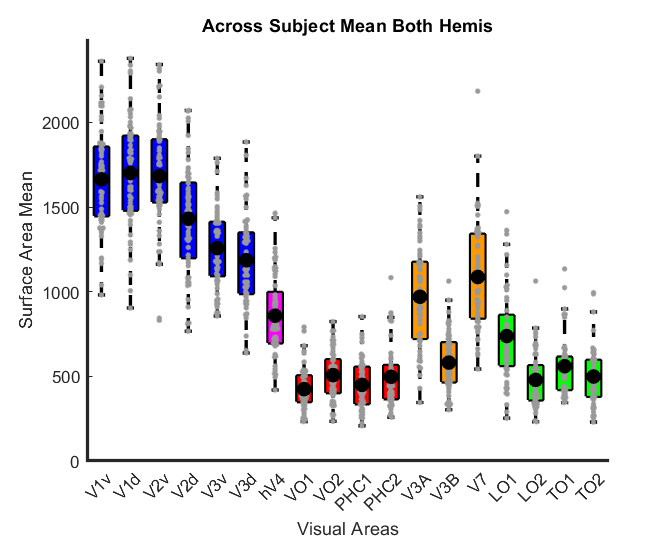

%% Plot distributions of area sizes
if strcmp(species,'Monks')
    use_colorscale=[0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 1; 1 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
else
     use_colorscale=[0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
end
use_colorscale_inv=flipud(use_colorscale);
figure
hold on
h=boxplot(retino_surfacearea_smoothwm_bothhemis','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(use_colorscale_inv(j,:)),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_bothhemis','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_bothhemis'),'k.','MarkerSize',30);
xlim([0.5 size(retino_surfacearea_smoothwm_bothhemis,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_bothhemis.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

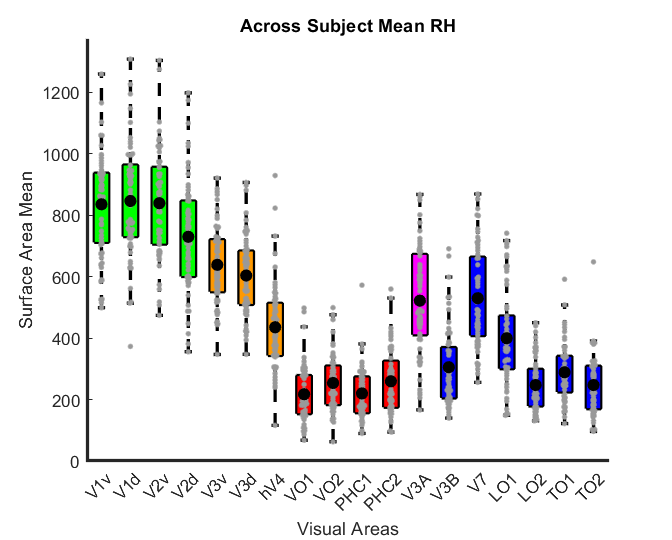


figure
hold on
h=boxplot(retino_surfacearea_smoothwm_rh','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_rh','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_rh'),'k.','MarkerSize',25);
xlim([0.5 size(retino_surfacearea_smoothwm_rh,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean RH')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_rh.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

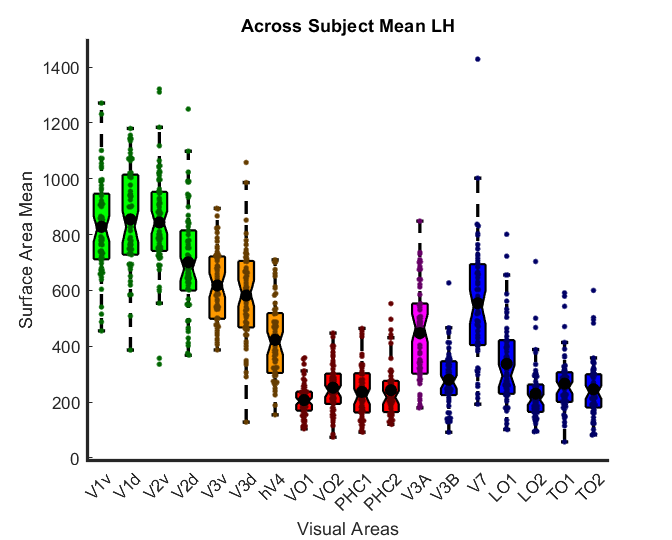


figure
hold on
h=boxplot(retino_surfacearea_smoothwm_lh','notch','on','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),flipud(use_colorscale(j,:)),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_lh','distributionColors',flipud(use_colorscale)*.4,'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_lh'),'k.','MarkerSize',25);
xlim([0.5 size(retino_surfacearea_smoothwm_lh,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean LH')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_lh.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

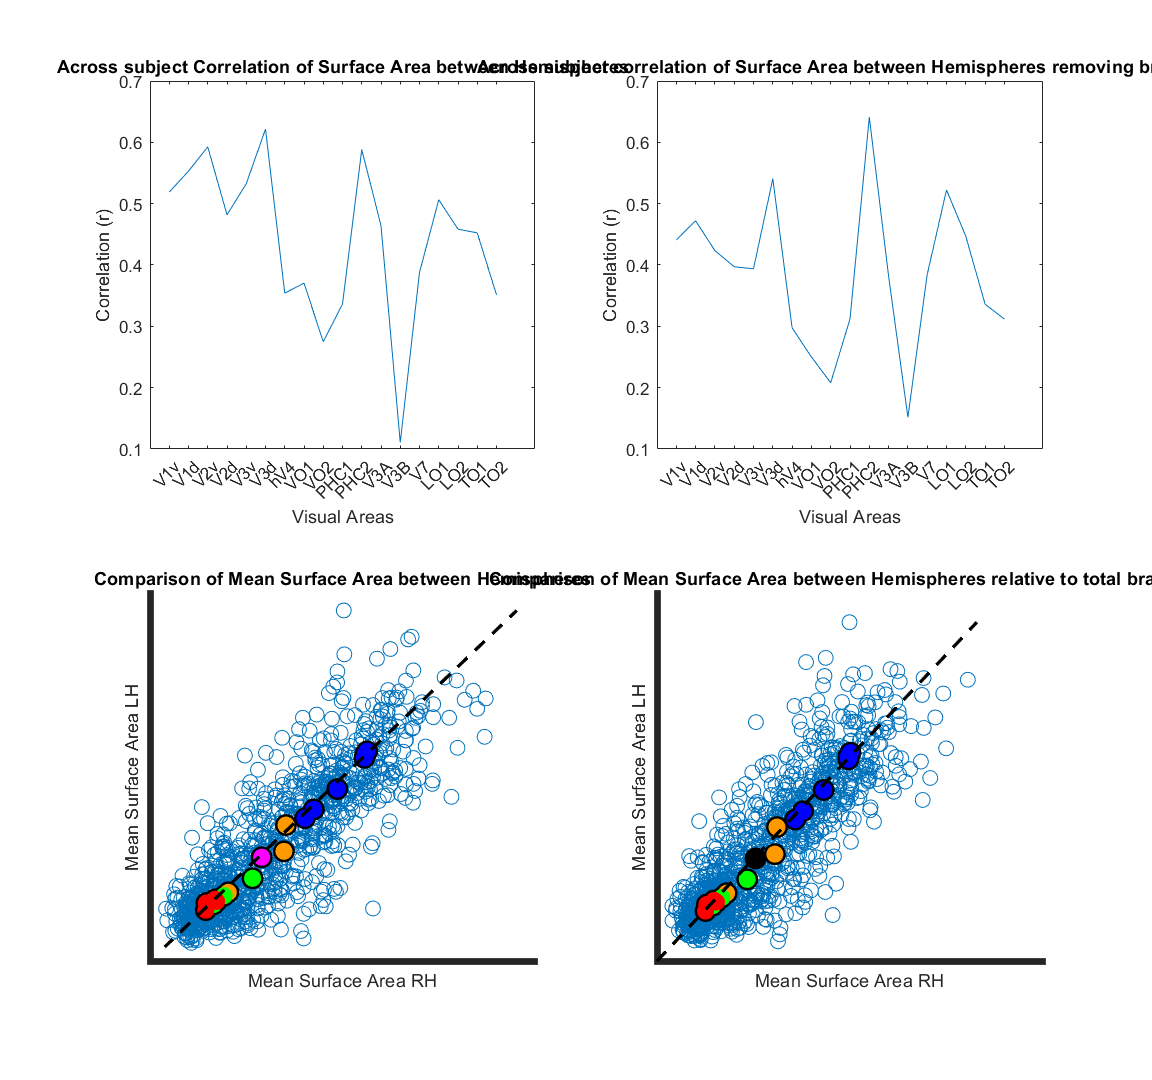

%% Comparisons of surface area between hemispheres
for curr_area = 1:size(retino_surfacearea_smoothwm_rh,1)
    crosshemi_array(curr_area)=corr(retino_surfacearea_smoothwm_rh(curr_area,:)',retino_surfacearea_smoothwm_lh(curr_area,:)','rows','complete');
    crosshemi_array_control(curr_area)=corr((retino_surfacearea_smoothwm_rh(curr_area,:)./total_surfacearea_rh)',(retino_surfacearea_smoothwm_lh(curr_area,:)./total_surfacearea_lh)','rows','complete');   
end
% have to run corr on each are separately be
%crosshemi_corrmatrix=corr(retino_surfacearea_smoothwm_rh',retino_surfacearea_smoothwm_lh','rows','complete');

figure
subplot(2,2,1)
plot(crosshemi_array)
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation (r)');
title('Across subject Correlation of Surface Area between Hemispheres')
subplot(2,2,2)
plot(crosshemi_array_control)
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation (r)');
title('Across subject correlation of Surface Area between Hemispheres removing brain size')
subplot(2,2,3)
scatter(retino_surfacearea_smoothwm_rh(:),retino_surfacearea_smoothwm_lh(:),80);
hold on
plot(nanmean(retino_surfacearea_smoothwm_rh,2),nanmean(retino_surfacearea_smoothwm_lh,2),'.k','MarkerSize',45);
plot(nanmean(retino_surfacearea_smoothwm_rh(EVCrois,:),2),nanmean(retino_surfacearea_smoothwm_lh(EVCrois,:),2),'.b','MarkerSize',35);
plot(nanmean(retino_surfacearea_smoothwm_rh(V4rois,:),2),nanmean(retino_surfacearea_smoothwm_lh(V4rois,:),2),'.','color',[1 0 1], 'MarkerSize',35);
plot(nanmean(retino_surfacearea_smoothwm_rh(dorsalrois,:),2),nanmean(retino_surfacearea_smoothwm_lh(dorsalrois,:),2),'.','color',[1 .6 0], 'MarkerSize',35);
plot(nanmean(retino_surfacearea_smoothwm_rh(lateralrois,:),2),nanmean(retino_surfacearea_smoothwm_lh(lateralrois,:),2),'.g','MarkerSize',35);
plot(nanmean(retino_surfacearea_smoothwm_rh(ventralrois,:),2),nanmean(retino_surfacearea_smoothwm_lh(ventralrois,:),2),'.r','MarkerSize',35);
%lsline
%max_value=ceil(max(max([nanmean(retino_surfacearea_smoothwm_rh,2),nanmean(retino_surfacearea_smoothwm_lh,2)])));
%min_value=floor(min(min([nanmean(retino_surfacearea_smoothwm_rh,2),nanmean(retino_surfacearea_smoothwm_lh,2)])));
max_value=max([max(retino_surfacearea_smoothwm_rh(:)),max(retino_surfacearea_smoothwm_lh(:))]);
min_value=floor([min(retino_surfacearea_smoothwm_rh(:)),min(retino_surfacearea_smoothwm_lh(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
title('Comparison of Mean Surface Area between Hemispheres')
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .95, .65]);
subplot(2,2,4)
retino_surfacearea_smoothwm_rh_norm=retino_surfacearea_smoothwm_rh./total_surfacearea_rh;
retino_surfacearea_smoothwm_lh_norm=retino_surfacearea_smoothwm_lh./total_surfacearea_lh;
scatter(retino_surfacearea_smoothwm_rh_norm(:),retino_surfacearea_smoothwm_lh_norm(:),80);
hold on
plot(nanmean(retino_surfacearea_smoothwm_rh_norm,2),nanmean(retino_surfacearea_smoothwm_lh_norm,2),'.k','MarkerSize',45);
plot(nanmean(retino_surfacearea_smoothwm_rh_norm(EVCrois,:),2),nanmean(retino_surfacearea_smoothwm_lh_norm(EVCrois,:),2),'.b','MarkerSize',35);
plot(nanmean(retino_surfacearea_smoothwm_rh_norm(V4rois,:),2),nanmean(retino_surfacearea_smoothwm_lh_norm(V4rois,:),2),'color',[1 0 1],'MarkerSize',35);
plot(nanmean(retino_surfacearea_smoothwm_rh_norm(dorsalrois,:),2),nanmean(retino_surfacearea_smoothwm_lh_norm(dorsalrois,:),2),'.','color',[1 .6 0], 'MarkerSize',35);
plot(nanmean(retino_surfacearea_smoothwm_rh_norm(lateralrois,:),2),nanmean(retino_surfacearea_smoothwm_lh_norm(lateralrois,:),2),'.g','MarkerSize',35);
plot(nanmean(retino_surfacearea_smoothwm_rh_norm(ventralrois,:),2),nanmean(retino_surfacearea_smoothwm_lh_norm(ventralrois,:),2),'.r','MarkerSize',35);
%lsline
hold on
%max_value=(max(max([nanmean(retino_surfacearea_smoothwm_rh./total_surfacearea_rh,2),nanmean(retino_surfacearea_smoothwm_lh./total_surfacearea_lh,2)])));
%min_value=(min(min([nanmean(retino_surfacearea_smoothwm_rh./total_surfacearea_rh,2),nanmean(retino_surfacearea_smoothwm_lh./total_surfacearea_lh,2)])));
max_value=max([nanmax(retino_surfacearea_smoothwm_rh_norm(:)),nanmax(retino_surfacearea_smoothwm_lh_norm(:))]);
min_value=floor([nanmin(retino_surfacearea_smoothwm_rh_norm(:)),nanmin(retino_surfacearea_smoothwm_lh_norm(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])
title('Comparison of Mean Surface Area between Hemispheres relative to total brain size')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .6, .9]);
pngFileName = ('CrossHemisphereComparisons.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

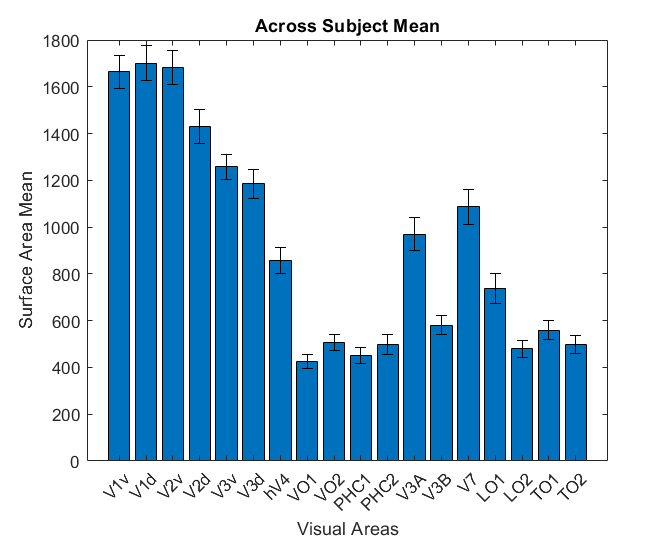

%% Bar graph showing across subject mean + standard error of surface area size for each visual area
figure
avgmeanbar = bar([1:length(allvisual_labels)], mean_retinoareas_bothhemis);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean')

hold on
er = errorbar([1:length(allvisual_labels)],mean_retinoareas_bothhemis,stderror_retinoareas_bothhemis);    
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectMean.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

hold off

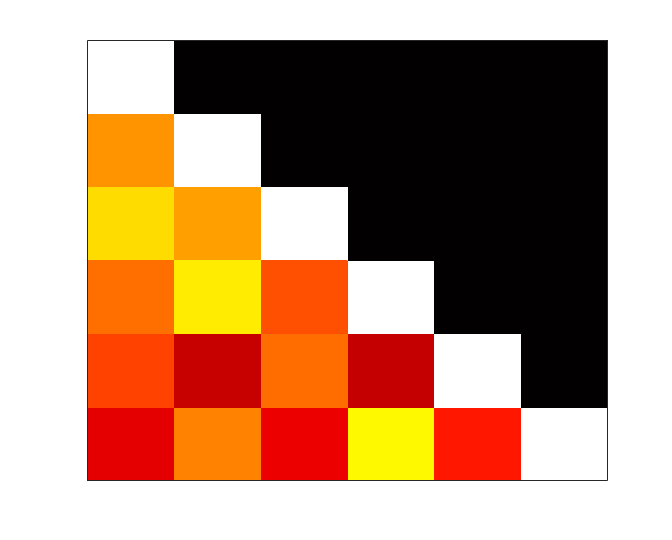

%% normalizing + plotting 

% For now, focus on nodearea smoothwm (add pial if you have time)
% run corr 
% to get around Nan: corr( X, Y, 'rows','complete')
% eg., corr( array of V3A sizes across subjects, array of V1 sizes)

%corr between all regions 

% hvae to create loop that takes each ROI from each subject --> nested for
% loops here --> okay 
%[rho,pval] = corr(V1_surfacearea, retino_surfacearea_smoothwm_bothhemis, 'complete');
%imagesc([r,l])

%normalize by V1 surface area 
%normalize by V1v surface area 
%normalize by V1d surface area

V1_surfacearea = (retino_surfacearea_smoothwm_bothhemis(1,:) + retino_surfacearea_smoothwm_bothhemis(2,:)); %full V1 of combined hemispheres 
V2_surfacearea = (retino_surfacearea_smoothwm_bothhemis(3,:) + retino_surfacearea_smoothwm_bothhemis(4,:)); %full V1 of combined hemispheres 
V3_surfacearea = (retino_surfacearea_smoothwm_bothhemis(5,:) + retino_surfacearea_smoothwm_bothhemis(6,:)); %full V1 of combined hemispheres 

V1v_surfacearea = retino_surfacearea_smoothwm_bothhemis(1,:);
V1d_surfacearea = retino_surfacearea_smoothwm_bothhemis(2,:);
V2v_surfacearea = retino_surfacearea_smoothwm_bothhemis(3,:);
V2d_surfacearea = retino_surfacearea_smoothwm_bothhemis(4,:);
V3v_surfacearea = retino_surfacearea_smoothwm_bothhemis(5,:);
V3d_surfacearea = retino_surfacearea_smoothwm_bothhemis(6,:);

if strcmp(species,'Monks')
    V4v_surfacearea = retino_surfacearea_smoothwm_bothhemis(7,:);
    V4d_surfacearea = retino_surfacearea_smoothwm_bothhemis(8,:);
    V4Av_surfacearea = retino_surfacearea_smoothwm_bothhemis(9,:);
    V4Ad_surfacearea = retino_surfacearea_smoothwm_bothhemis(10,:);
    DVcombined=[V1v_surfacearea;V1d_surfacearea;V2v_surfacearea;V2d_surfacearea;V3v_surfacearea;V3d_surfacearea;V4v_surfacearea;V4d_surfacearea;V4Av_surfacearea;V4Ad_surfacearea]
    
else
    DVcombined=[V1v_surfacearea;V1d_surfacearea;V2v_surfacearea;V2d_surfacearea;V3v_surfacearea;V3d_surfacearea];
end
DVcombined_corr=corr(DVcombined','rows','complete');
DVcombined_corr(triu(true(size(DVcombined_corr,1)),1)) = 0;
imagesc(DVcombined_corr,[0 1])
colormap('hot')
set(gca,'xtick',[])
set(gca,'ytick',[])

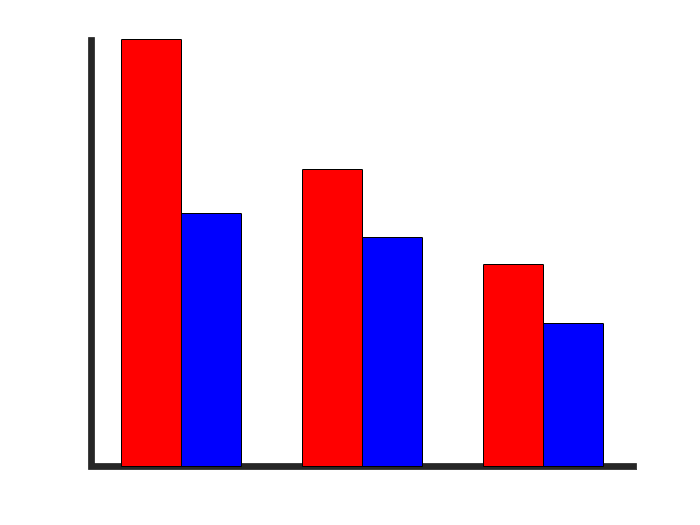


DVcombined_corr=corr(DVcombined','rows','complete');
figure 
hold on
bar([1, 4, 7], DVcombined_corr(1:2:6,1), .33 ,'r')
bar([2, 5, 8], DVcombined_corr(2:2:6,1), .33, 'b')
xlim([0 9])
ylim([0 1])
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])

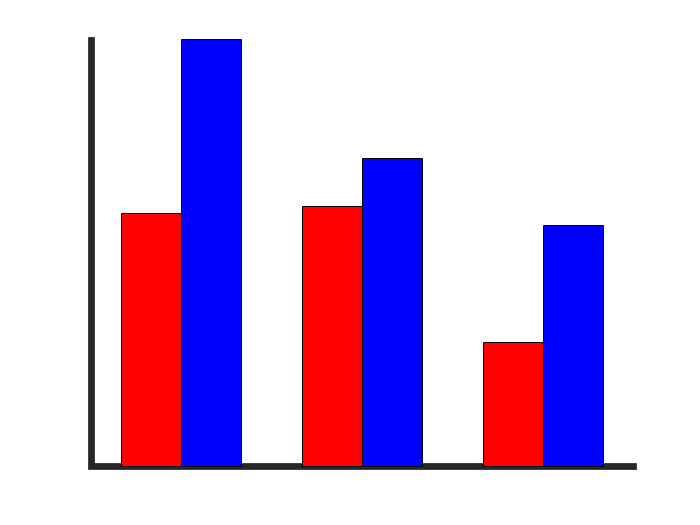


figure 
hold on
bar([1, 4, 7], DVcombined_corr(1:2:6,2), .33 ,'r')
bar([2, 5, 8], DVcombined_corr(2:2:6,2), .33, 'b')
xlim([0 9])
ylim([0 1])
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])

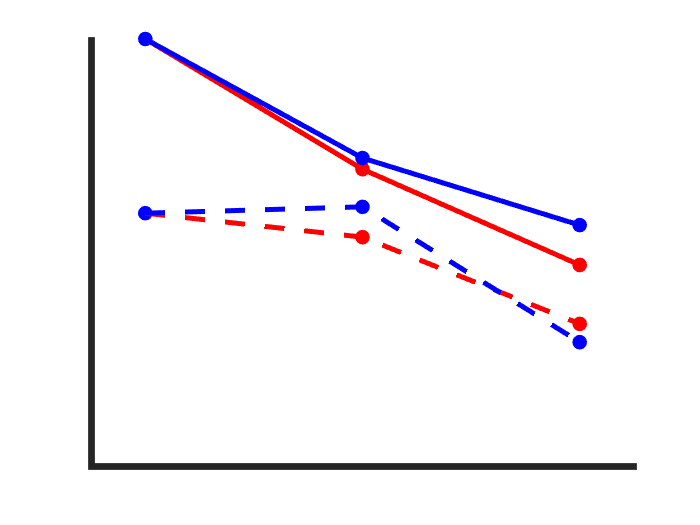


DVcombined_corr=corr(DVcombined','rows','complete');
if strcmp(species,'Monks')
    figure
    hold on
    plot(DVcombined_corr(1:2:10,1),'.r','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(2:2:10,2),'.b','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(2:2:10,1),'.r','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(1:2:10,2),'.b','LineWidth',3,'MarkerSize',30)

    plot(DVcombined_corr(1:2:10,1),'-r','LineWidth',3)
    plot(DVcombined_corr(2:2:10,2),'-b','LineWidth',3)
    plot(DVcombined_corr(2:2:10,1),'--r','LineWidth',3)
    plot(DVcombined_corr(1:2:10,2),'--b','LineWidth',3)
    xlim([.75 5.25])
    ylim([0 1])
    set(gca,'linewidth',4)
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    
else
    figure
    hold on
    plot(DVcombined_corr(1:2:6,1),'.r','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(2:2:6,2),'.b','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(2:2:6,1),'.r','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(1:2:6,2),'.b','LineWidth',3,'MarkerSize',30)

    plot(DVcombined_corr(1:2:6,1),'-r','LineWidth',3)
    plot(DVcombined_corr(2:2:6,2),'-b','LineWidth',3)
    plot(DVcombined_corr(2:2:6,1),'--r','LineWidth',3)
    plot(DVcombined_corr(1:2:6,2),'--b','LineWidth',3)
    xlim([.75 3.25])
    ylim([0 1])
    set(gca,'linewidth',4)
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    
end

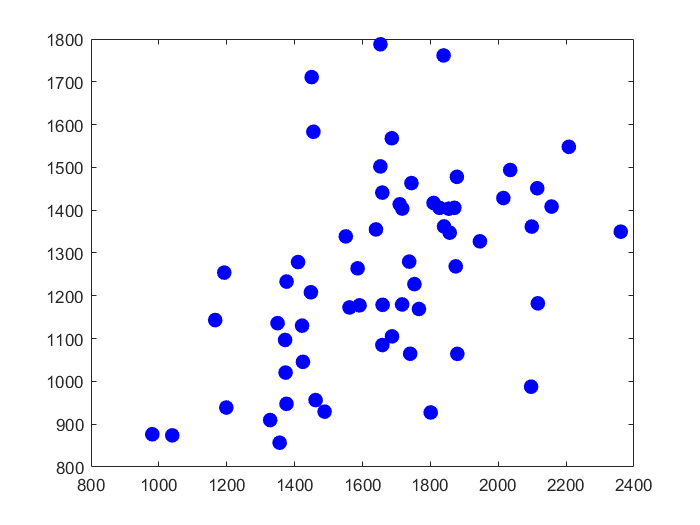

    
% 
% DVcombined_corr=corr(DVcombined','rows','complete');
% figure 
% hold on
% bar([1, 4, 7], DVcombined_corr(1:2:6,5), .33 ,'r')
% bar([2, 5, 8], DVcombined_corr(2:2:6,5), .33, 'b')
% xlim([0 9])
% ylim([0 1])
% 
% figure 
% hold on
% bar([1, 4, 7], DVcombined_corr(1:2:6,6), .33 ,'r')
% bar([2, 5, 8], DVcombined_corr(2:2:6,6), .33, 'b')
% xlim([0 9])
% ylim([0 1])


withinDV=[V1v_surfacearea,V1v_surfacearea,V2v_surfacearea;V2v_surfacearea,V3v_surfacearea,V3v_surfacearea];
betweenDV=[V1v_surfacearea,V1v_surfacearea,V2v_surfacearea;V2d_surfacearea,V3d_surfacearea,V3d_surfacearea];

V1DVcorrelations=[DVcombined_corr(1,:),DVcombined_corr(:,1)',DVcombined_corr(2,:),DVcombined_corr(:,2)'];
V1DVcorrelations=V1DVcorrelations(V1DVcorrelations>0 & V1DVcorrelations<1);

V2DVcorrelations=[DVcombined_corr(3,:),DVcombined_corr(:,3)',DVcombined_corr(4,:),DVcombined_corr(:,4)'];
V2DVcorrelations=V2DVcorrelations(V2DVcorrelations>0 & V2DVcorrelations<1);

V3DVcorrelations=[DVcombined_corr(5,:),DVcombined_corr(:,5)',DVcombined_corr(6,:),DVcombined_corr(:,6)'];
V3DVcorrelations=V3DVcorrelations(V3DVcorrelations>0 & V3DVcorrelations<1);

if strcmp(species,'Monks')
V4DVcorrelations=[DVcombined_corr(7,:),DVcombined_corr(:,7)',DVcombined_corr(8,:),DVcombined_corr(:,8)'];
V4DVcorrelations=V4DVcorrelations(V4DVcorrelations>0 & V4DVcorrelations<1);

V4ADVcorrelations=[DVcombined_corr(9,:),DVcombined_corr(:,9)',DVcombined_corr(10,:),DVcombined_corr(:,10)'];
V4ADVcorrelations=V4ADVcorrelations(V4ADVcorrelations>0 & V4ADVcorrelations<1);
end

figure
plot(V1v_surfacearea,V3v_surfacearea,'.b','Markersize',30)

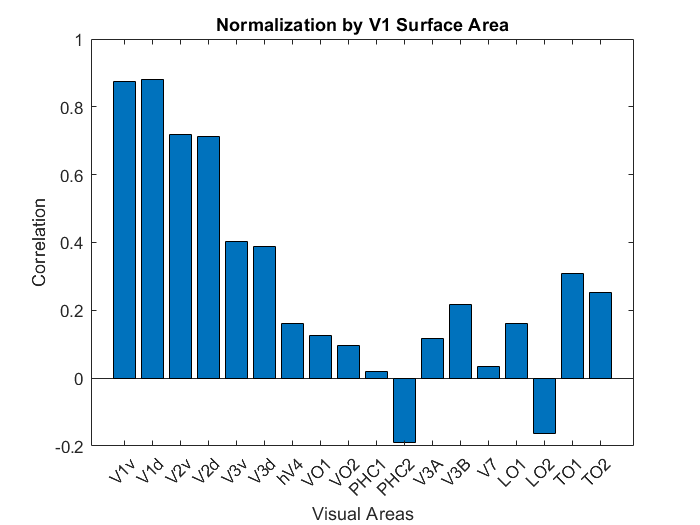


V3A_surfacearea = retino_surfacearea_smoothwm_bothhemis(7,:); %7 if Humans %11 if monks

 
%human areas
hV4_surfacearea = retino_surfacearea_smoothwm_bothhemis(14,:);
TO1_surfacearea = retino_surfacearea_smoothwm_bothhemis(12,:); 


%concatenated surfaceareas 
V1_surfacearea_cat = (retino_surfacearea_smoothwm_catbothhemis(1,:) + retino_surfacearea_smoothwm_catbothhemis(2,:));
V2_surfacearea_cat = (retino_surfacearea_smoothwm_catbothhemis(3,:) + retino_surfacearea_smoothwm_catbothhemis(4,:));
V3_surfacearea_cat = (retino_surfacearea_smoothwm_catbothhemis(5,:) + retino_surfacearea_smoothwm_catbothhemis(6,:));


N = size(retino_surfacearea_smoothwm_bothhemis, 1);
%corr_V1 = zeros(1,N);
if strcmp(species,'Monks')
    use_colorscale=[0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 1; 1 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
else
     use_colorscale=[0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
end
corr_V1 = corr(V1_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
figure
barV1= bar([1:length(allvisual_labels)],corr_V1);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1 Surface Area')


corr_V1_cat = corr(V1_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete')

corr_V1_cat =     0.8211    0.8622    0.5123    0.5544    0.2951    0.3761    0.1749    0.1142    0.1013    0.1439   -0.1092    0.0966    0.0952    0.0875    0.1644   -0.1050    0.3018    0.1655


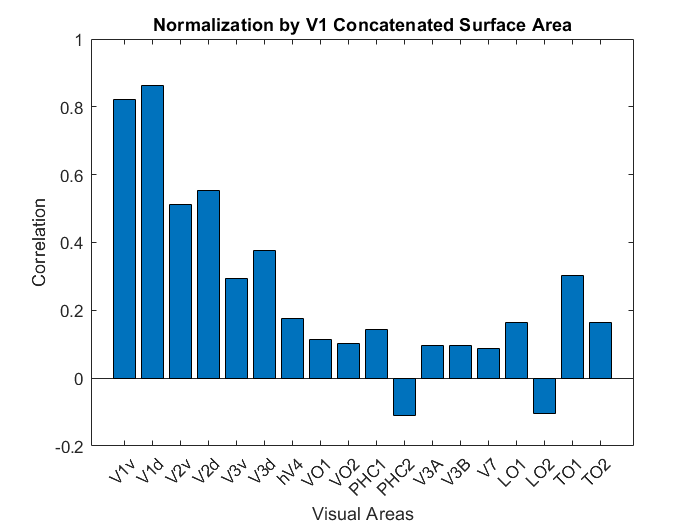

figure
barV1cat= bar([1:length(allvisual_labels)],corr_V1_cat);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1 Concatenated Surface Area')

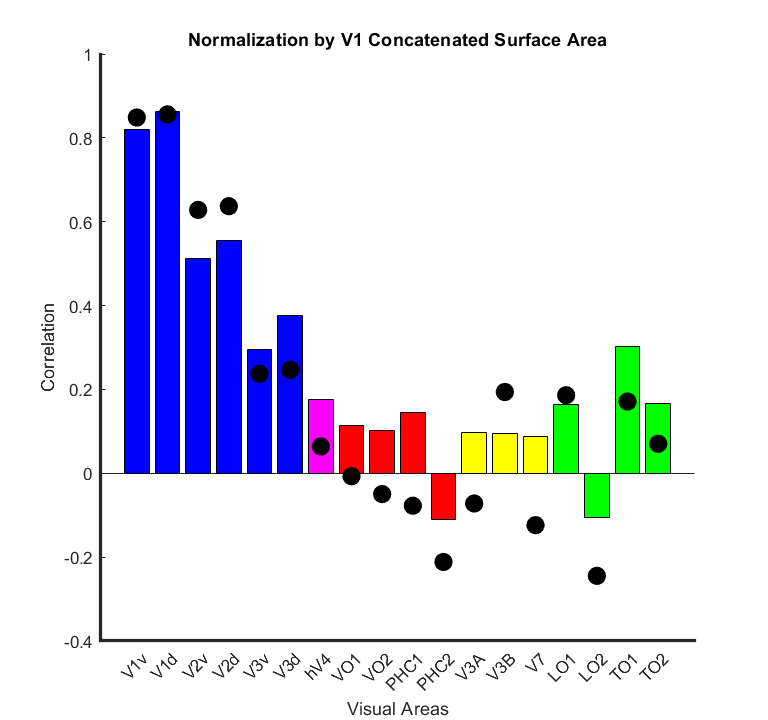


corr_V1_cat = corr(V1_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
figure
hold on
bar([EVCrois],corr_V1_cat(EVCrois),'b');
bar([V4rois],corr_V1_cat(V4rois),'m');
bar([ventralrois],corr_V1_cat(ventralrois),'r');
bar([dorsalrois],corr_V1_cat(dorsalrois),'y');
bar([lateralrois],corr_V1_cat(lateralrois),'g');
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1 Concatenated Surface Area')
hold on
pcorr_V1 = partialcorr(V1_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
scatter([1:length(pcorr_V1)],pcorr_V1,'k','filled','SizeData',120)
hold off
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .4, .6]);
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];

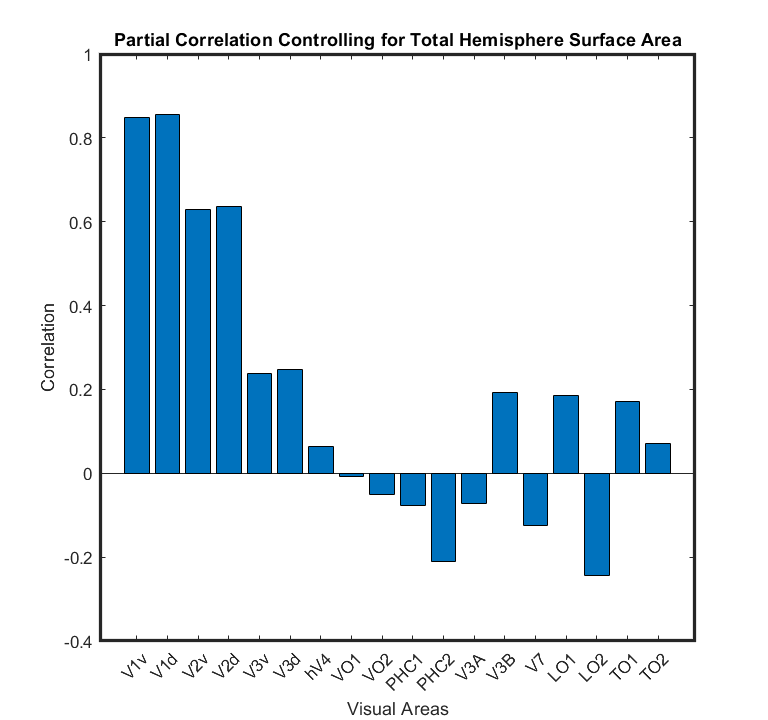


%partial corr V1: right and left hemisphere surface area
pcorr_V1 = partialcorr(V1_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV1 = bar([1:length(allvisual_labels)],pcorr_V1);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

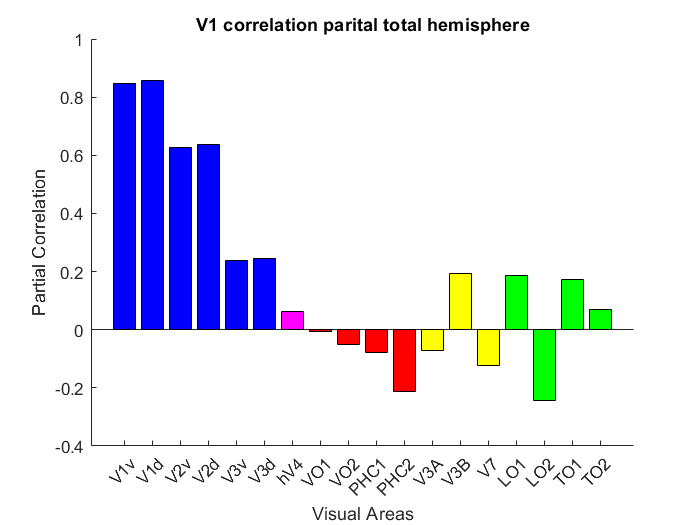

figure
hold on
bar([EVCrois],pcorr_V1(EVCrois),'b');
bar([V4rois],pcorr_V1(V4rois),'m');
bar([ventralrois],pcorr_V1(ventralrois),'r');
bar([dorsalrois],pcorr_V1(dorsalrois),'y');
bar([lateralrois],pcorr_V1(lateralrois),'g');
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Partial Correlation');
title('V1 correlation parital total hemisphere')

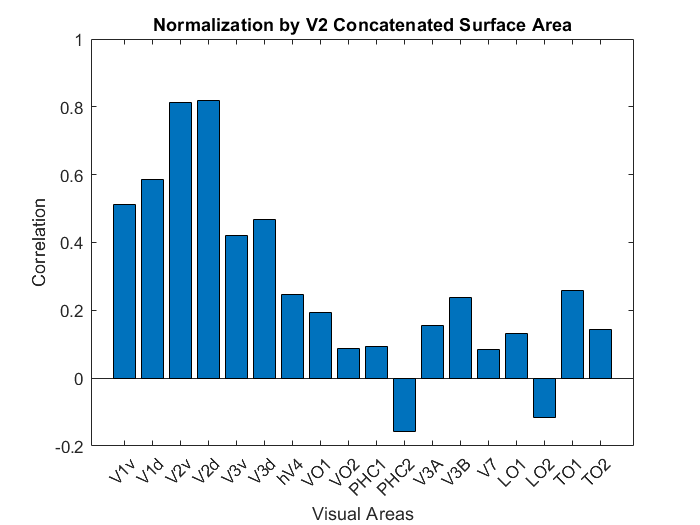



corr_V2_cat = corr(V2_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
figure
barV2cat= bar([1:length(allvisual_labels)],corr_V2_cat);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V2 Concatenated Surface Area')

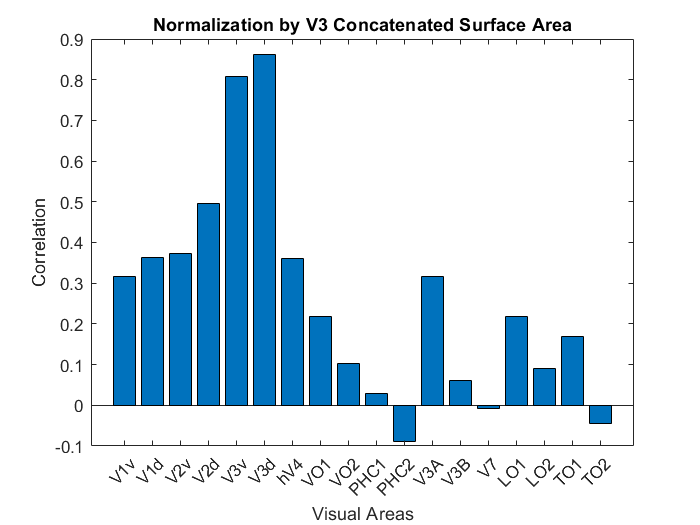


corr_V3_cat = corr(V3_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
figure
barV3cat= bar([1:length(allvisual_labels)],corr_V3_cat);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V3 Concatenated Surface Area')

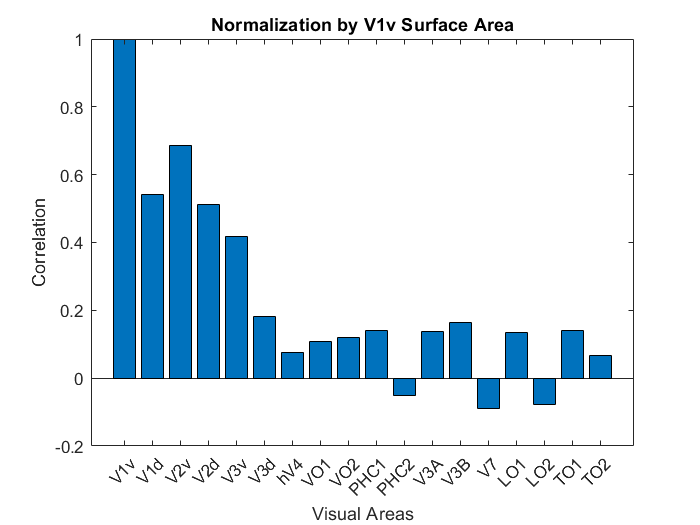


corr_V1v =  corr(V1v_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
figure
barV1v= bar([1:length(allvisual_labels)],corr_V1v);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1v Surface Area')

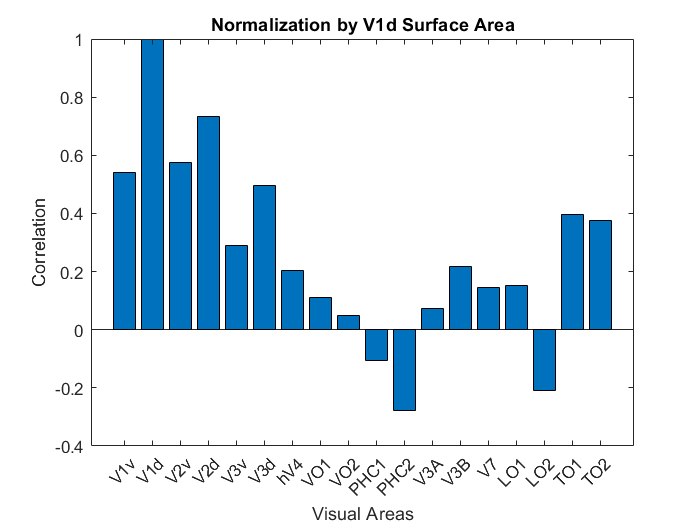



corr_V1d = corr(V1d_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
figure
barV1d= bar([1:length(allvisual_labels)],corr_V1d);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1d Surface Area')

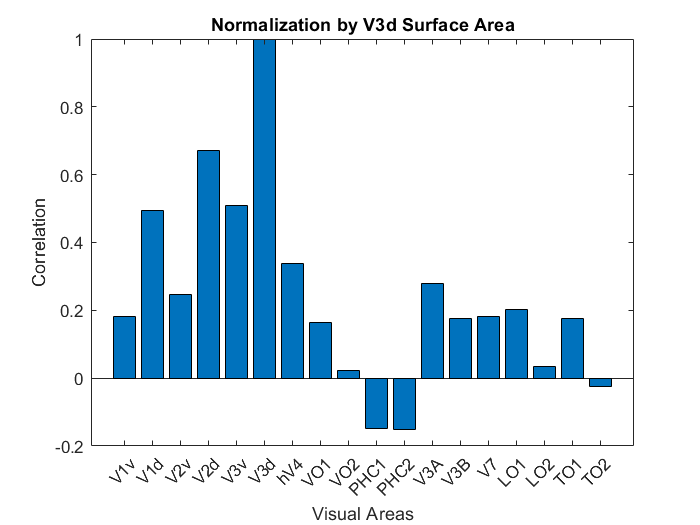



corr_V3d = corr(V3d_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
figure
barV1d= bar([1:length(allvisual_labels)],corr_V3d);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V3d Surface Area')

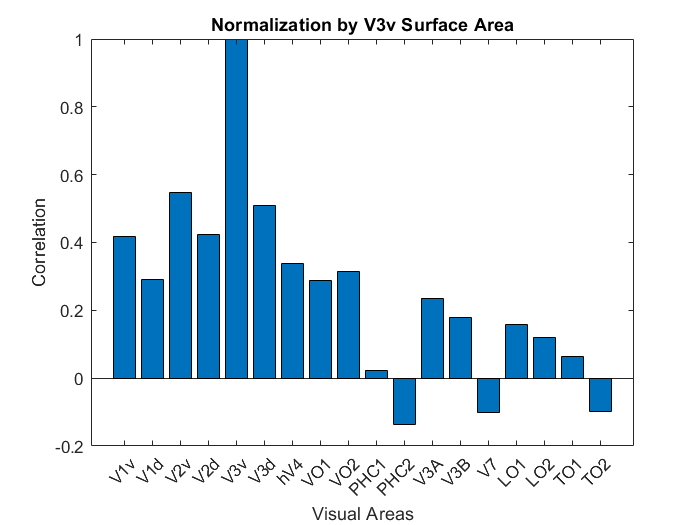


corr_V3v = corr(V3v_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
figure
barV1d= bar([1:length(allvisual_labels)],corr_V3v);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V3v Surface Area')

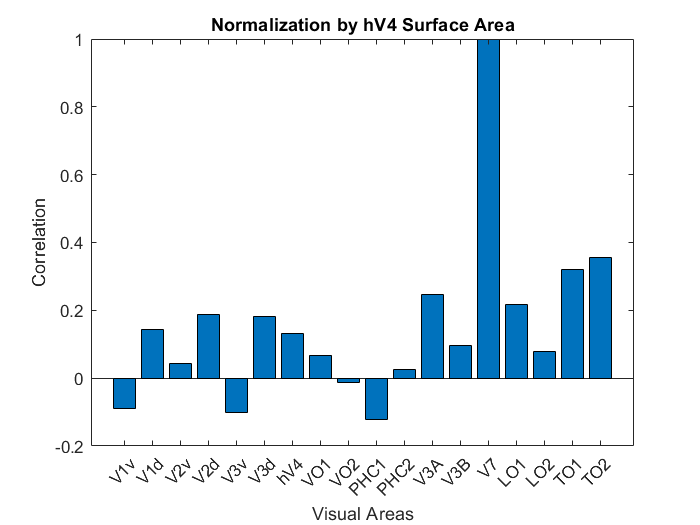


corr_hV4 = corr(hV4_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
barV1d= bar([1:length(allvisual_labels)],corr_hV4);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by hV4 Surface Area')

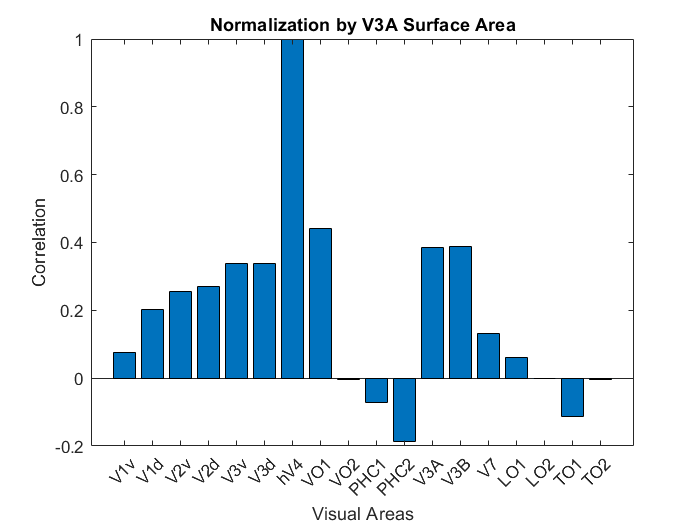


corr_V3A = corr(V3A_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
figure
barV1d= bar([1:length(allvisual_labels)],corr_V3A);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V3A Surface Area')

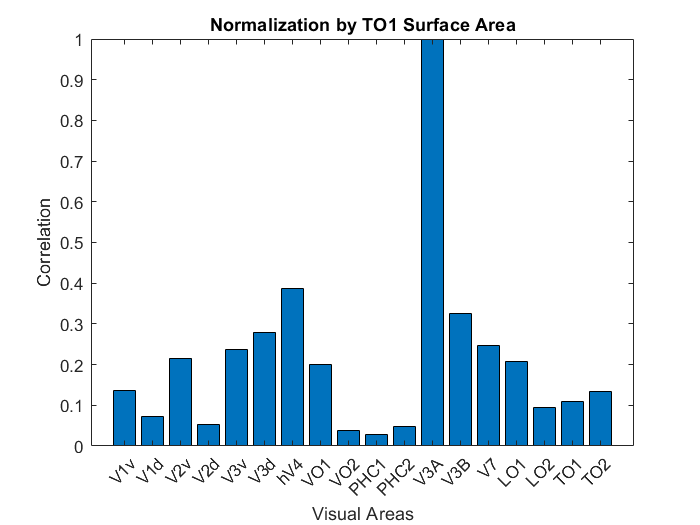


corr_TO1 = corr(TO1_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
barV1d= bar([1:length(allvisual_labels)],corr_TO1);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by TO1 Surface Area')

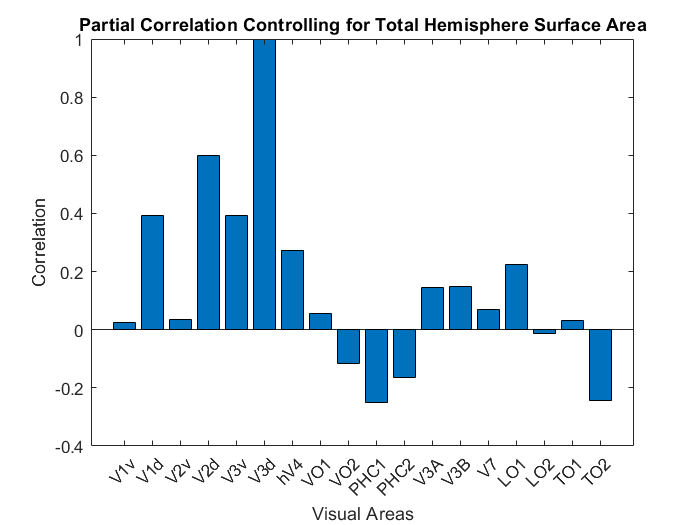

%% Partial Correlations 

%partial corr V3d: right and left hemisphere surface area
pcorr_V3d = partialcorr(V3d_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV3d = bar([1:length(allvisual_labels)],pcorr_V3d);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

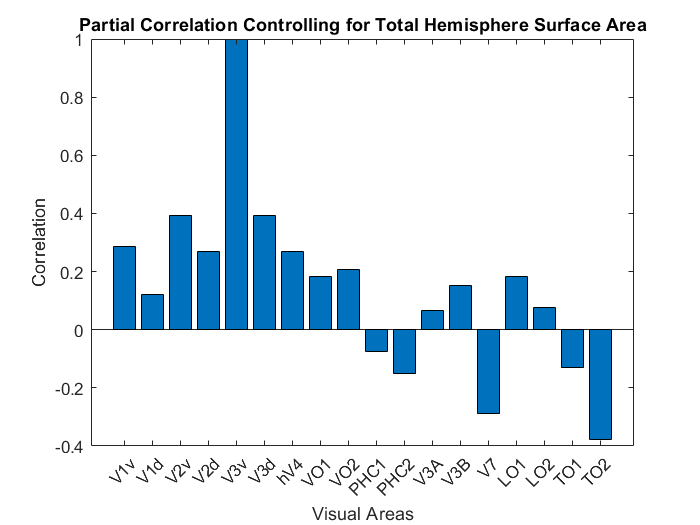



%partial corr V3v: right and left hemisphere surface area
pcorr_V3v = partialcorr(V3v_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV3v = bar([1:length(allvisual_labels)],pcorr_V3v);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

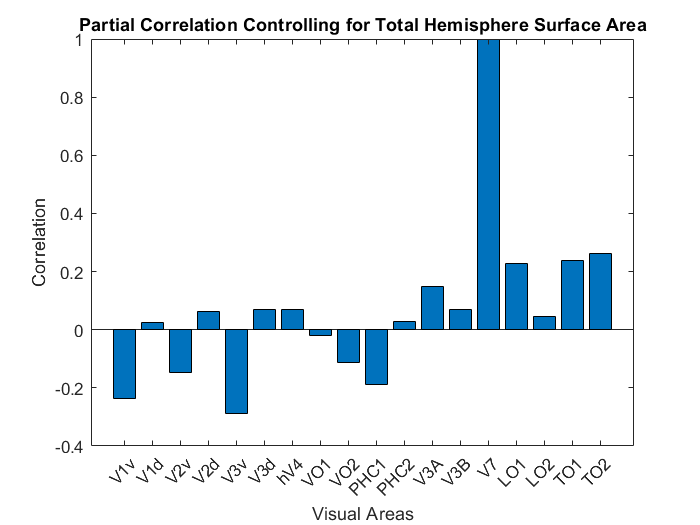



%partial corr hV4: right and left hemisphere surface area
pcorr_hV4 = partialcorr(hV4_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barhV4 = bar([1:length(allvisual_labels)],pcorr_hV4);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

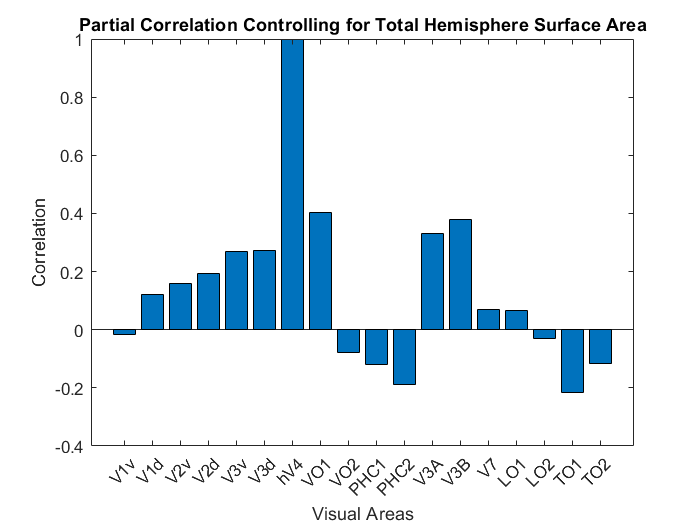



%partial corr V3A: right and left hemisphere surface area
pcorr_V3A = partialcorr(V3A_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV3A = bar([1:length(allvisual_labels)],pcorr_V3A);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

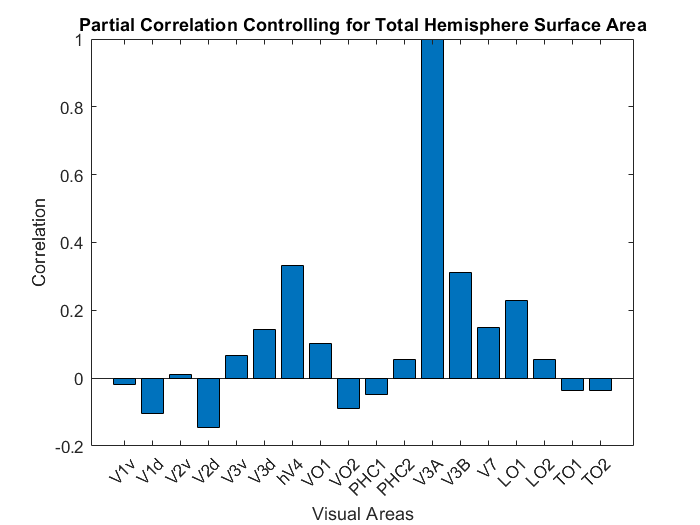




%partial corr TO1: right and left hemisphere surface area
pcorr_TO1 = partialcorr(TO1_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barTO1 = bar([1:length(allvisual_labels)],pcorr_TO1);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

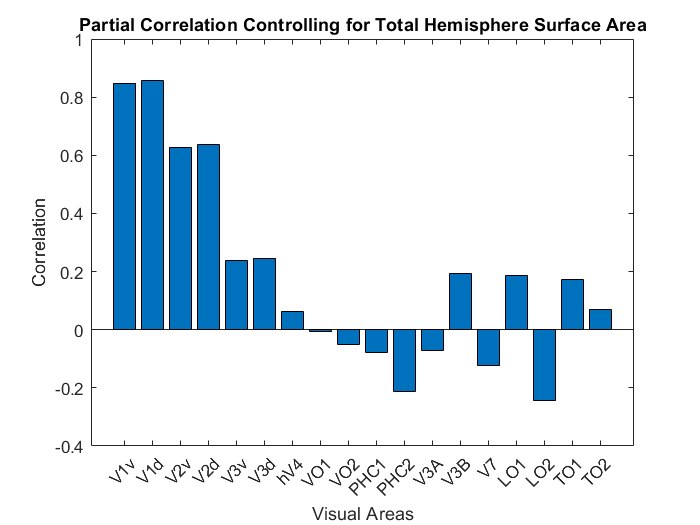



%partial corr V1: right and left hemisphere surface area
pcorr_V1 = partialcorr(V1_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV1 = bar([1:length(allvisual_labels)],pcorr_V1);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

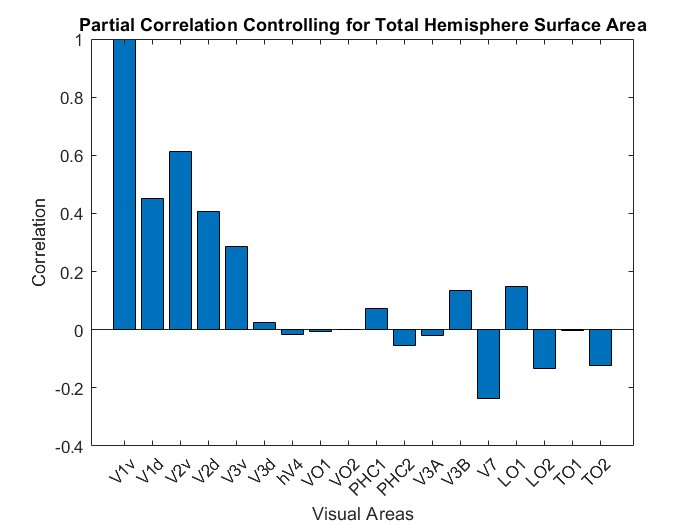



%partial corr V1v: right and left hemisphere surface area
pcorr_V1v = partialcorr(V1v_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV1v = bar([1:length(allvisual_labels)],pcorr_V1v);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

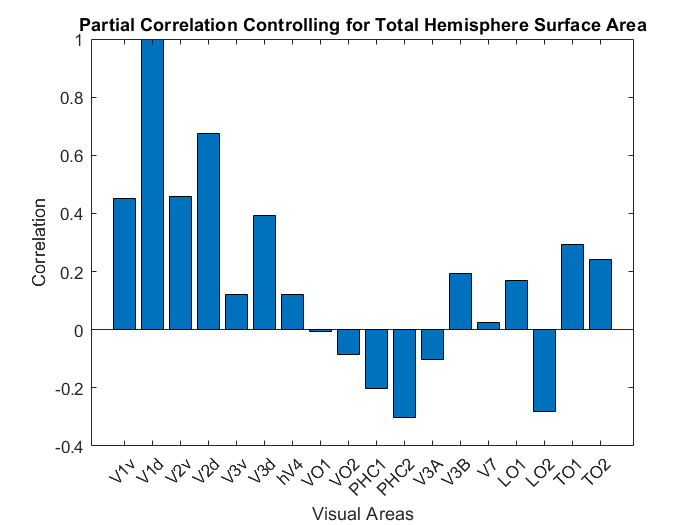


%partial corr V1d: right and left hemisphere surface area
pcorr_V1d = partialcorr(V1d_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV1d = bar([1:length(allvisual_labels)],pcorr_V1d);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

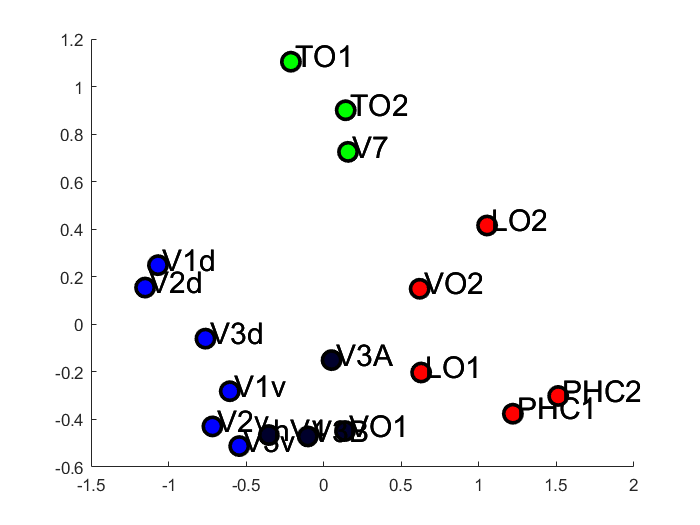



% RSA 
%just for humans? 
retino_surfacearea_simmatrix=corr(retino_surfacearea_smoothwm_bothhemis','rows','complete');
plotModularity(retino_surfacearea_simmatrix,allvisual_labels,'newmansq');

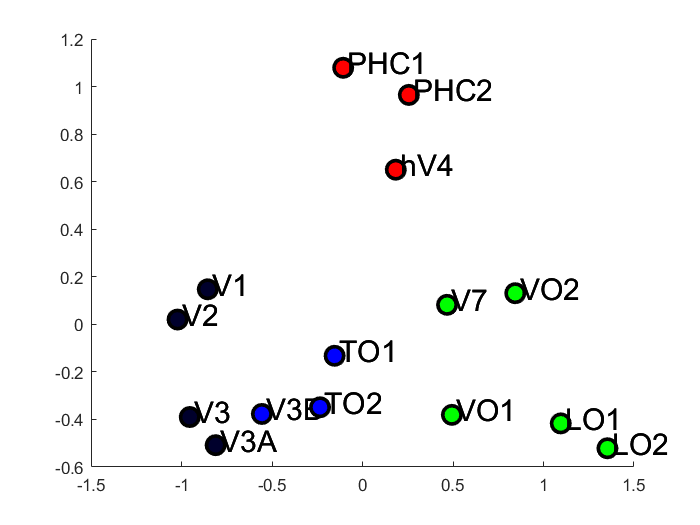


retino_surfacearea_smoothwm_bothhemis_noquadrants=retino_surfacearea_smoothwm_bothhemis;
retino_surfacearea_smoothwm_bothhemis_noquadrants(1,:)=retino_surfacearea_smoothwm_bothhemis_noquadrants(1,:)+retino_surfacearea_smoothwm_bothhemis_noquadrants(2,:);
retino_surfacearea_smoothwm_bothhemis_noquadrants(2,:)=retino_surfacearea_smoothwm_bothhemis_noquadrants(3,:)+retino_surfacearea_smoothwm_bothhemis_noquadrants(4,:);
retino_surfacearea_smoothwm_bothhemis_noquadrants(3,:)=retino_surfacearea_smoothwm_bothhemis_noquadrants(5,:)+retino_surfacearea_smoothwm_bothhemis_noquadrants(6,:);
retino_surfacearea_smoothwm_bothhemis_noquadrants(4,:)=[];
retino_surfacearea_smoothwm_bothhemis_noquadrants(5,:)=[];
retino_surfacearea_smoothwm_bothhemis_noquadrants(6,:)=[];
allvisual_labels_noquadrants={'V1','V2','V3','V3A','V3B','V7','LO1','LO2','TO1','TO2','hV4','VO1','VO2','PHC1','PHC2'};

retino_surfacearea_noquadrants_simmatrix=corr(retino_surfacearea_smoothwm_bothhemis_noquadrants','rows','complete');
plotModularity(retino_surfacearea_noquadrants_simmatrix,allvisual_labels_noquadrants,'newmansq');  %gives error when monks 

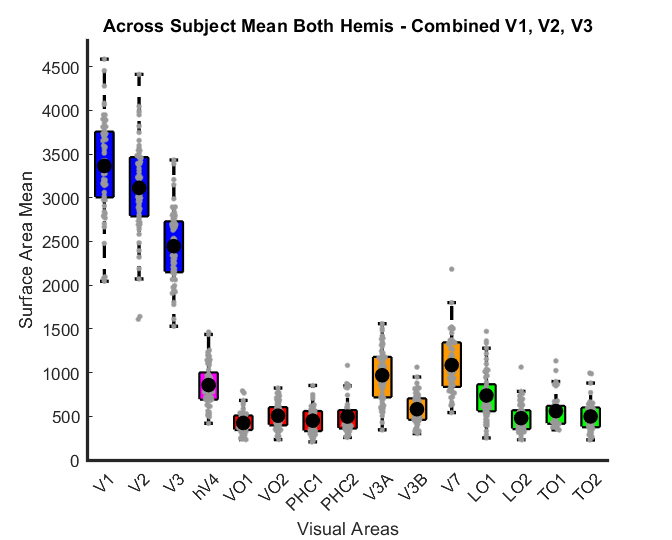

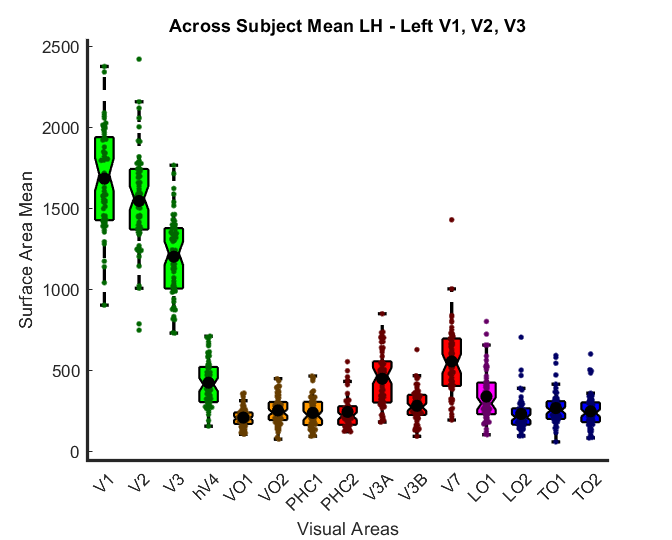

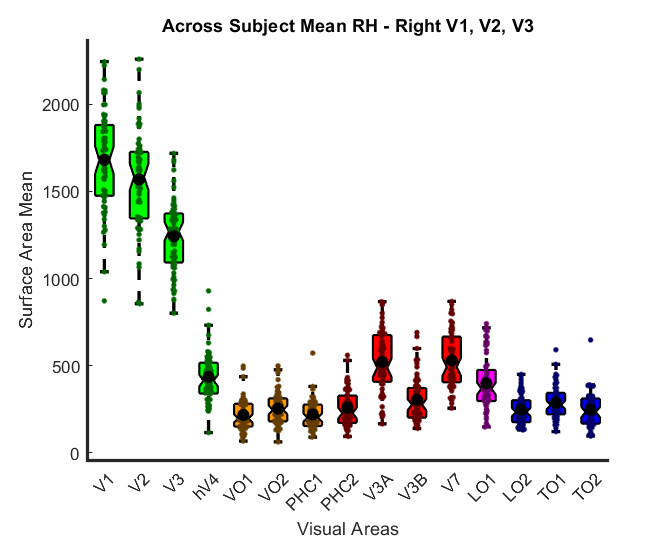

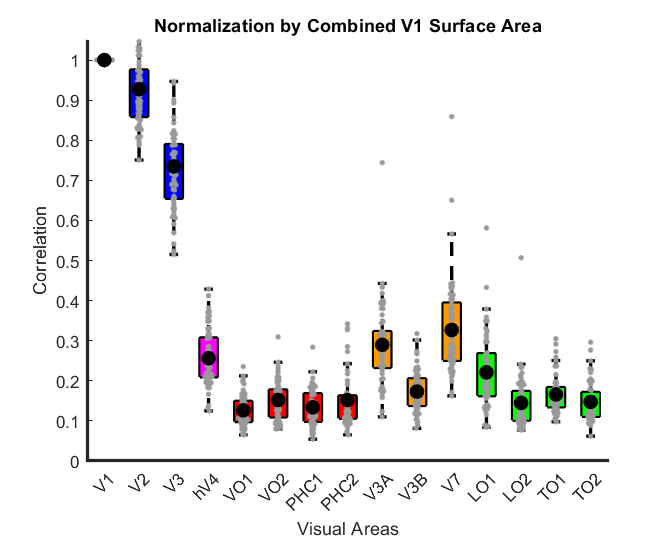

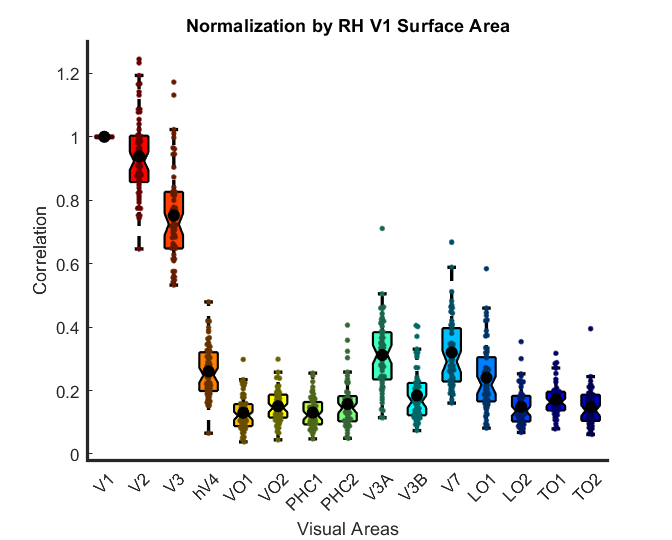

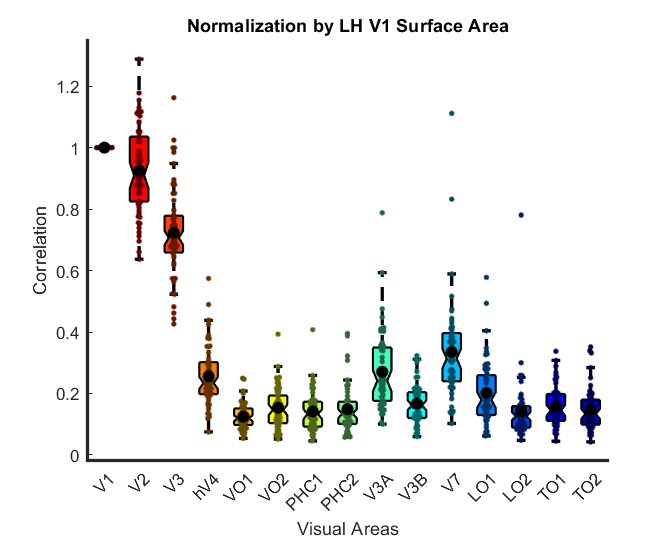

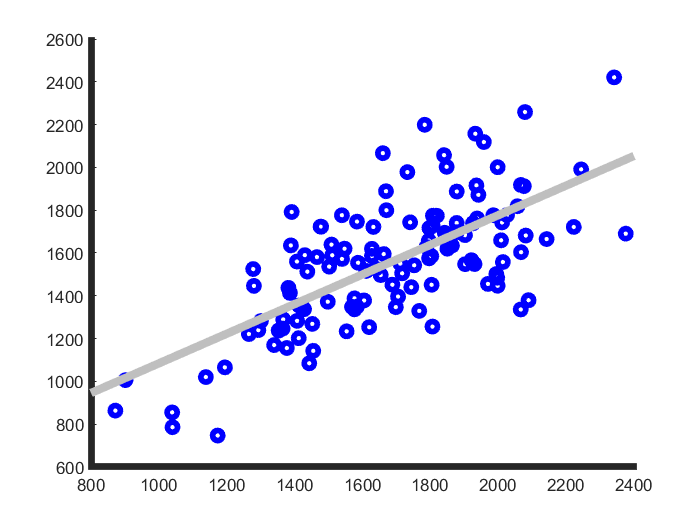

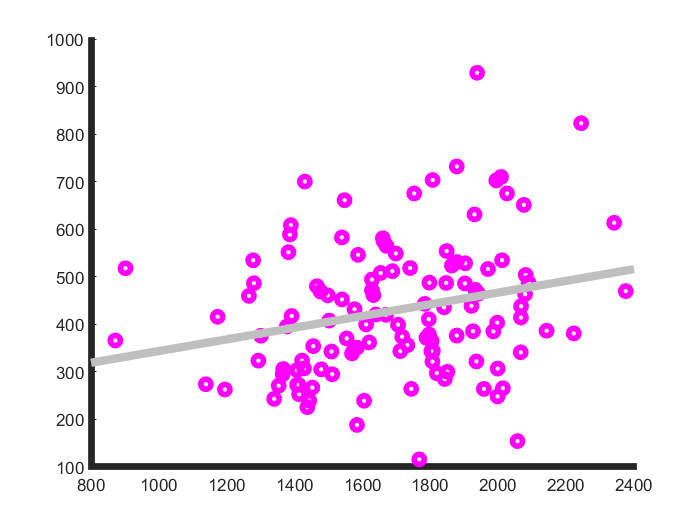



%% More direct Comparisons

monks = 0; %turn on/off certain graphs

%for monkeys 
if monks == 1 
    
allvisual_labels_combined_monks = {'V1', 'V2', 'V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};
%Combined V1, V2, V3, V4, V4A- monks
V1_combined = retino_surfacearea_smoothwm_bothhemis(1,:) + retino_surfacearea_smoothwm_bothhemis(2,:);
V2_combined = retino_surfacearea_smoothwm_bothhemis(3,:) + retino_surfacearea_smoothwm_bothhemis(4,:);
V3_combined = retino_surfacearea_smoothwm_bothhemis(5,:) + retino_surfacearea_smoothwm_bothhemis(6,:);
V4_combined = retino_surfacearea_smoothwm_bothhemis(7,:) + retino_surfacearea_smoothwm_bothhemis(8,:);
V4A_combined = retino_surfacearea_smoothwm_bothhemis(9,:) + retino_surfacearea_smoothwm_bothhemis(10,:);

retino_surfacearea_smoothwm_bothhemis_combinedV1234 = [V1_combined;V2_combined;V3_combined;V4_combined;V4A_combined;retino_surfacearea_smoothwm_bothhemis(11:26,:)]; 


%use_colorscale=jet(size(retino_surfacearea_smoothwm_bothhemis_combinedV1234,1));
use_colorscale=[0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
use_colorscale_inv=flipud(use_colorscale);
figure
hold on
h=boxplot(retino_surfacearea_smoothwm_bothhemis_combinedV1234','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_bothhemis_combinedV1234','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234'),'k.','MarkerSize',30);
xlim([0.5 size(retino_surfacearea_smoothwm_bothhemis_combinedV1234,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
ylim([0 2000])
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis - Combined V1, V2, V3, V4, V4A')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_bothhemis_combinedV1234.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

bar(nanstd(retino_surfacearea_smoothwm_bothhemis_combinedV1234,[],2)./nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234,2))

retino_surfacearea_smoothwm_bothhemis_combinedV1234_normV1=retino_surfacearea_smoothwm_bothhemis_combinedV1234./repmat(retino_surfacearea_smoothwm_bothhemis_combinedV1234(1,:),[size(retino_surfacearea_smoothwm_bothhemis_combinedV1234,1) 1]);
bar(nanstd(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normV1,[],2)./nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normV1,2))

retino_surfacearea_smoothwm_bothhemis_combinedV1234_normMT=retino_surfacearea_smoothwm_bothhemis_combinedV1234./repmat(retino_surfacearea_smoothwm_bothhemis_combinedV1234(13,:),[size(retino_surfacearea_smoothwm_bothhemis_combinedV1234,1) 1]);
bar(nanstd(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normMT,[],2)./nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normMT,2))


retino_surfacearea_bothhemis_combinedV1234_normtotalbrain=retino_surfacearea_smoothwm_bothhemis_combinedV1234./repmat(total_surfacearea_bothhemis(1,:),[size(retino_surfacearea_smoothwm_bothhemis_combinedV1234,1) 1]);

retino_surfacearea_smoothwm_bothhemis_combinedV1234_normbrainV1=retino_surfacearea_bothhemis_combinedV1234_normtotalbrain./repmat(retino_surfacearea_bothhemis_combinedV1234_normtotalbrain(1,:),[size(retino_surfacearea_bothhemis_combinedV1234_normtotalbrain,1) 1]);
bar(nanstd(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normbrainV1,[],2)./nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normbrainV1,2))



V1_catcombined = retino_surfacearea_smoothwm_catbothhemis(1,:) + retino_surfacearea_smoothwm_catbothhemis(2,:);
V2_catcombined = retino_surfacearea_smoothwm_catbothhemis(3,:) + retino_surfacearea_smoothwm_catbothhemis(4,:);
V3_catcombined = retino_surfacearea_smoothwm_catbothhemis(5,:) + retino_surfacearea_smoothwm_catbothhemis(6,:);
V4_catcombined = retino_surfacearea_smoothwm_catbothhemis(7,:) + retino_surfacearea_smoothwm_catbothhemis(8,:);
V4A_catcombined = retino_surfacearea_smoothwm_catbothhemis(9,:) + retino_surfacearea_smoothwm_catbothhemis(10,:);

retino_surfacearea_smoothwm_catbothhemis_combinedV123 = [V1_catcombined;V2_catcombined;V3_catcombined;V4_catcombined;V4A_catcombined;retino_surfacearea_smoothwm_catbothhemis(11:end,:)]; 
allvisual_labels_combined_monks = {'V1', 'V2', 'V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};
figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(2,:),10+x,'b')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];

figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(4,:),10+x,'m')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];


figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(18,:),10+x,'g')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];


%Left Hemishphere 
V1_combined_lh = retino_surfacearea_smoothwm_lh(1,:) + retino_surfacearea_smoothwm_lh(2,:);
V2_combined_lh = retino_surfacearea_smoothwm_lh(3,:) + retino_surfacearea_smoothwm_lh(4,:);
V3_combined_lh = retino_surfacearea_smoothwm_lh(5,:) + retino_surfacearea_smoothwm_lh(6,:);
V4_combined_lh = retino_surfacearea_smoothwm_lh(7,:) + retino_surfacearea_smoothwm_lh(8,:);
V4A_combined_lh = retino_surfacearea_smoothwm_lh(9,:) + retino_surfacearea_smoothwm_lh(10,:);

retino_surfacearea_smoothwm_leftV1234 = [V1_combined_lh;V2_combined_lh;V3_combined_lh;V4_combined_lh;V4A_combined_lh;retino_surfacearea_smoothwm_lh(11:26,:)]; 

%use_colorscale=jet(size(retino_surfacearea_smoothwm_leftV1234,1));
use_colorscale=[0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];

figure
hold on
h=boxplot(retino_surfacearea_smoothwm_leftV1234','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_leftV1234','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_leftV1234'),'k.','MarkerSize',30);
xlim([0.5 size(retino_surfacearea_smoothwm_leftV1234,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean LH - Left V1, V2, V3, V4, V4A')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_leftV1234.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 


%Right Hemisphere 
V1_combined_rh = retino_surfacearea_smoothwm_rh(1,:) + retino_surfacearea_smoothwm_rh(2,:);
V2_combined_rh = retino_surfacearea_smoothwm_rh(3,:) + retino_surfacearea_smoothwm_rh(4,:);
V3_combined_rh = retino_surfacearea_smoothwm_rh(5,:) + retino_surfacearea_smoothwm_rh(6,:);
V4_combined_rh = retino_surfacearea_smoothwm_rh(7,:) + retino_surfacearea_smoothwm_rh(8,:);
V4A_combined_rh = retino_surfacearea_smoothwm_rh(9,:) + retino_surfacearea_smoothwm_rh(10,:);

retino_surfacearea_smoothwm_rightV1234 = [V1_combined_rh;V2_combined_rh;V3_combined_rh;V4_combined_rh;V4A_combined_rh;retino_surfacearea_smoothwm_rh(11:26,:)]; 



%use_colorscale=jet(size(retino_surfacearea_smoothwm_rightV1234,1));
use_colorscale=[0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];

figure
hold on
h=boxplot(retino_surfacearea_smoothwm_rightV1234','notch','on','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_rightV1234','distributionColors',flipud(use_colorscale)*.4,'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_rightV1234'),'k.','MarkerSize',25);
xlim([0.5 size(retino_surfacearea_smoothwm_rightV1234,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean RH - Right V1, V2, V3, V4, V4A')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 2000])
pngFileName = ('AcrossSubjectDistribution_rightV1234.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

%% Normalization by V1 graph - for each subject, divide other areas by V1 

%combined hemis V1
normv1_combined = retino_surfacearea_smoothwm_bothhemis_combinedV1234./V1_combined;
% normv1_combined = mean(normv1_combined,2, 'omitnan');
% figure
% barV1combined = bar(normv1_combined);
% set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
% xlabel('Visual Areas');
% ylabel('Correlation');
% title('Normalization by Combined V1 Surface Area')
% pngFileName = ('Normalization_CombinedV1.png');
% fullFileName = fullfile(save_folder, pngFileName);
% saveas(gcf, fullFileName); 

%use_colorscale=jet(size(normv1_combined,1));
use_colorscale=[0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];

figure
hold on
h=boxplot(normv1_combined','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(normv1_combined','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(normv1_combined'),'k.','MarkerSize',30);
xlim([0.5 size(normv1_combined,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
ylim([0 1])
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('Normalization_CombinedV1.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 


%right hemi
normv1_rh = retino_surfacearea_smoothwm_rightV1234./V1_combined_rh;

use_colorscale=jet(size(normv1_rh,1));
figure
hold on
h=boxplot(normv1_rh','notch','on','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(normv1_rh','distributionColors',flipud(use_colorscale)*.4,'spreadWidth',.5)
plot(nanmean(normv1_rh'),'k.','MarkerSize',25);
xlim([0.5 size(normv1_rh,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by RH V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('Normalization_RH_V1.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

%left hemi
normv1_lh = retino_surfacearea_smoothwm_leftV1234./V1_combined_lh;

use_colorscale=jet(size(normv1_lh,1));
figure
hold on
h=boxplot(normv1_lh','notch','on','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(normv1_lh','distributionColors',flipud(use_colorscale)*.4,'spreadWidth',.5)
plot(nanmean(normv1_lh'),'k.','MarkerSize',25);
xlim([0.5 size(normv1_lh,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by LH V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('Normalization_LH_V1.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 


else %plot human graphs 
    
allvisual_labels_combined = {'V1', 'V2', 'V3','hV4','VO1','VO2','PHC1','PHC2', 'V3A','V3B','V7','LO1','LO2','TO1','TO2'}; 
%Combined V1, V2, V3 
V1_combined = retino_surfacearea_smoothwm_bothhemis(1,:) + retino_surfacearea_smoothwm_bothhemis(2,:);
V2_combined = retino_surfacearea_smoothwm_bothhemis(3,:) + retino_surfacearea_smoothwm_bothhemis(4,:);
V3_combined = retino_surfacearea_smoothwm_bothhemis(5,:) + retino_surfacearea_smoothwm_bothhemis(6,:);

retino_surfacearea_smoothwm_bothhemis_combinedV123 = [V1_combined;V2_combined;V3_combined;retino_surfacearea_smoothwm_bothhemis(7:18,:)]; 

%use_colorscale=jet(size(retino_surfacearea_smoothwm_bothhemis_combinedV123,1));
 use_colorscale=[0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
use_colorscale_inv=flipud(use_colorscale);
figure
hold on
h=boxplot(retino_surfacearea_smoothwm_bothhemis_combinedV123','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_bothhemis_combinedV123','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV123'),'k.','MarkerSize',30);
xlim([0.5 size(retino_surfacearea_smoothwm_bothhemis_combinedV123,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis - Combined V1, V2, V3')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_bothhemis_combinedV123.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

%Left Hemishphere 
V1_combined_lh = retino_surfacearea_smoothwm_lh(1,:) + retino_surfacearea_smoothwm_lh(2,:);
V2_combined_lh = retino_surfacearea_smoothwm_lh(3,:) + retino_surfacearea_smoothwm_lh(4,:);
V3_combined_lh = retino_surfacearea_smoothwm_lh(5,:) + retino_surfacearea_smoothwm_lh(6,:);

retino_surfacearea_smoothwm_leftV123 = [V1_combined_lh;V2_combined_lh;V3_combined_lh;retino_surfacearea_smoothwm_lh(7:18,:)]; 

%use_colorscale=jet(size(retino_surfacearea_smoothwm_leftV123,1));
use_colorscale=[0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
figure
hold on
h=boxplot(retino_surfacearea_smoothwm_leftV123','notch','on','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_leftV123','distributionColors',flipud(use_colorscale)*.4,'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_leftV123'),'k.','MarkerSize',25);
xlim([0.5 size(retino_surfacearea_smoothwm_leftV123,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean LH - Left V1, V2, V3')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_leftV123.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 


%Right Hemisphere 
V1_combined_rh = retino_surfacearea_smoothwm_rh(1,:) + retino_surfacearea_smoothwm_rh(2,:);
V2_combined_rh = retino_surfacearea_smoothwm_rh(3,:) + retino_surfacearea_smoothwm_rh(4,:);
V3_combined_rh = retino_surfacearea_smoothwm_rh(5,:) + retino_surfacearea_smoothwm_rh(6,:);

retino_surfacearea_smoothwm_rightV123 = [V1_combined_rh;V2_combined_rh;V3_combined_rh;retino_surfacearea_smoothwm_rh(7:18,:)]; 

%use_colorscale=jet(size(retino_surfacearea_smoothwm_rightV123,1));
 use_colorscale=[0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
figure
hold on
h=boxplot(retino_surfacearea_smoothwm_rightV123','notch','on','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_rightV123','distributionColors',flipud(use_colorscale)*.4,'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_rightV123'),'k.','MarkerSize',25);
xlim([0.5 size(retino_surfacearea_smoothwm_rightV123,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean RH - Right V1, V2, V3')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_rightV123.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

%Normalization by V1 graph - for each subject, divide other areas by V1 

%combined hemis V1
normv1_combined = retino_surfacearea_smoothwm_bothhemis_combinedV123./V1_combined;
 use_colorscale=[0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
use_colorscale_inv=flipud(use_colorscale);
%use_colorscale=jet(size(normv1_combined,1));
figure
hold on
h=boxplot(normv1_combined','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(normv1_combined','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(normv1_combined'),'k.','MarkerSize',30);
xlim([0.5 size(normv1_combined,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 1.05])
pngFileName = ('Normalization_CombinedV1.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 



%right hemi
normv1_rh = retino_surfacearea_smoothwm_rightV123./V1_combined_rh;
use_colorscale=jet(size(normv1_rh,1));
figure
hold on
h=boxplot(normv1_rh','notch','on','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(normv1_rh','distributionColors',flipud(use_colorscale)*.4,'spreadWidth',.5)
plot(nanmean(normv1_rh'),'k.','MarkerSize',25);
xlim([0.5 size(normv1_rh,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by RH V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('Normalization_RH_V1.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

%left hemi
normv1_lh = retino_surfacearea_smoothwm_leftV123./V1_combined_lh;
use_colorscale=jet(size(normv1_lh,1));
figure
hold on
h=boxplot(normv1_lh','notch','on','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(normv1_lh','distributionColors',flipud(use_colorscale)*.4,'spreadWidth',.5)
plot(nanmean(normv1_lh'),'k.','MarkerSize',25);
xlim([0.5 size(normv1_lh,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by LH V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('Normalization_LH_V1.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 



V1_catcombined = retino_surfacearea_smoothwm_catbothhemis(1,:) + retino_surfacearea_smoothwm_catbothhemis(2,:);
V2_catcombined = retino_surfacearea_smoothwm_catbothhemis(3,:) + retino_surfacearea_smoothwm_catbothhemis(4,:);
V3_catcombined = retino_surfacearea_smoothwm_catbothhemis(5,:) + retino_surfacearea_smoothwm_catbothhemis(6,:);

retino_surfacearea_smoothwm_catbothhemis_combinedV123 = [V1_catcombined;V2_catcombined;V3_catcombined;retino_surfacearea_smoothwm_catbothhemis(7:end,:)]; 

% for curr_roi=1:size(retino_surfacearea_smoothwm_catbothhemis_combinedV123,1)
%     V1corrs(curr_roi)=corr(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,~isnan(retino_surfacearea_smoothwm_catbothhemis_combinedV123(curr_roi,:)))',retino_surfacearea_smoothwm_catbothhemis_combinedV123(curr_roi,~isnan(retino_surfacearea_smoothwm_catbothhemis_combinedV123(curr_roi,:)))');
% end

figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(2,:),10+x,'b')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];

figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(4,:),10+x,'m')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];


figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(14,:),10+x,'g')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];

figure
hold on
scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:)/nanmean(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:)),retino_surfacearea_smoothwm_catbothhemis_combinedV123(2,:)/nanmean(retino_surfacearea_smoothwm_catbothhemis_combinedV123(2,:)),80)
scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:)/nanmean(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:)),retino_surfacearea_smoothwm_catbothhemis_combinedV123(4,:)/nanmean(retino_surfacearea_smoothwm_catbothhemis_combinedV123(4,:)),80)

corr_V1_cat = corr(V1_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
figure
barV1cat= bar([1:length(allvisual_labels)],corr_V1_cat);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1 Concatenated Surface Area')

end


allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,52,53,54,55,56,100,101,102,103];

meanavgdist_allsubjs_rh=nanmean(avgdist_allsubjs_rh,2);
meanavgdist_allsubjs_lh=nanmean(avgdist_allsubjs_lh,2);


## this part has a bug/doesn't make sense

% rh_rois=Read_1D('allvisual-rh.1D.dset');
% lh_rois=Read_1D('allvisual-lh.1D.dset');
% rh_avgdist_rois=rh_rois;
% rh_avgdist_rois(rh_rois(:,2)==1,2)=0.05;
% rh_avgdist_rois(rh_rois(:,2)==2,2)=0.05;
% lh_avgdist_rois=lh_rois;
% lh_avgdist_rois(lh_rois(:,2)==1,2)=0.05;
% lh_avgdist_rois(lh_rois(:,2)==2,2)=0.05;
% for curr_roi = 3: length(allvisual_numbers)
%     rh_avgdist_rois(rh_rois(:,2)==allvisual_numbers(curr_roi),2)=meanavgdist_allsubjs_rh(curr_roi);
%     lh_avgdist_rois(lh_rois(:,2)==allvisual_numbers(curr_roi),2)=meanavgdist_allsubjs_lh(curr_roi);
% end
% 
% dlmwrite('rh_avgdist_rois.1D.dset',rh_avgdist_rois)
% dlmwrite('lh_avgdist_rois.1D.dset',lh_avgdist_rois)

% eg., partialcorr( array of V3A sizes across subjects, array of V1 sizes, array total surface area)
% across subjects)

% create correlation matrix: area x area correlations
% create partial correlation matrix: area x area correlations removing
% total area
% create partial correlation matrix: area x area correlations removing
% V1 area
